clear; close all; clc

% Read data in
nasa_turbofan = load("train_FD001.txt");
disp(nasa_turbofan);

   1.0e+03 *

    0.0010    0.0010   -0.0000   -0.0000    0.1000    0.5187    0.6418    1.5897    1.4006    0.0146    0.0216    0.5544    2.3881    9.0462    0.0013    0.0475    0.5217    2.3880    8.1386    0.0084    0.0000    0.3920    2.3880    0.1000    0.0391    0.0234
    0.0010    0.0020    0.0000   -0.0000    0.1000    0.5187    0.6421    1.5918    1.4031    0.0146    0.0216    0.5537    2.3880    9.0441    0.0013    0.0475    0.5223    2.3881    8.1315    0.0084    0.0000    0.3920    2.3880    0.1000    0.0390    0.0234
    0.0010    0.0030   -0.0000    0.0000    0.1000    0.5187    0.6423    1.5880    1.4042    0.0146    0.0216    0.5543    2.3881    9.0529    0.0013    0.0473    0.5224    2.3880    8.1332    0.0084    0.0000    0.3900    2.3880    0.1000    0.0390    0.0233
    0.0010    0.0040    0.0000         0    0.1000    0.5187    0.6423    1.5828    1.4019    0.0146    0.0216    0.5544    2.3881    9.0495    0.0013    0.0471    0.5229    2.3881    8.1338    0.0084   

total_columns = size(nasa_turbofan, 2);
% Set first 5 column names
first_five_cols = {'unit_number', 'time_in_cycles', 'operational_setting_1', 'operational_setting_2', 'operational_setting_3'};  
sensor_columns_amount = total_columns - length(first_five_cols);

% Create sensor_columns
sensor_columns = arrayfun(@(x) sprintf('sensor_measurement_%d', x), 1:sensor_columns_amount, 'UniformOutput', false);

% All columns
column_labels = [first_five_cols, sensor_columns];

## RUL Calculation


% Extract all data for column1(engineId) and column2(cycle count) 
iteration = nasa_turbofan(:, 1);
cycle_count = nasa_turbofan(:, 2);

% Initialize RUL vector preallocating with zeros
RUL = zeros(size(cycle_count));

% filter engine IDs
unique_engines = unique(iteration);

% calculate RUL for each engine
for i = 1:length(unique_engines)
    engine_id = unique_engines(i);

    % Find indices for the current engine
    engine_indices = find(iteration == engine_id);

    % Determine the last cycle after which failure occurs
    max_cycle = max(cycle_count(engine_indices));

    % Calculate RUL for all cycles of this engine
    RUL(engine_indices) = max_cycle - cycle_count(engine_indices);
    
    % Print the first 50 cycles for the each engine
    fprintf('RUL for first 50 Cycles for Engine ID %d:\n', engine_id);
    for cycle_idx = 1:min(50, length(engine_indices)) 
        % tracking current cycle number
        current_cycle = cycle_count(engine_indices(cycle_idx)); 
        % tracking current RUL
        current_RUL = RUL(engine_indices(cycle_idx));  
        
        % Print the cycle number, engine ID, and RUL
        fprintf('Cycle %d: Engine ID %d, RUL: %d\n', current_cycle, engine_id, current_RUL);
    end
    
    fprintf('\n'); % Adds a new line between engines for better readability
end

RUL for first 50 Cycles for Engine ID 1:


Cycle 1: Engine ID 1, RUL: 191
Cycle 2: Engine ID 1, RUL: 190
Cycle 3: Engine ID 1, RUL: 189
Cycle 4: Engine ID 1, RUL: 188
Cycle 5: Engine ID 1, RUL: 187
Cycle 6: Engine ID 1, RUL: 186
Cycle 7: Engine ID 1, RUL: 185
Cycle 8: Engine ID 1, RUL: 184
Cycle 9: Engine ID 1, RUL: 183
Cycle 10: Engine ID 1, RUL: 182
Cycle 11: Engine ID 1, RUL: 181
Cycle 12: Engine ID 1, RUL: 180
Cycle 13: Engine ID 1, RUL: 179
Cycle 14: Engine ID 1, RUL: 178
Cycle 15: Engine ID 1, RUL: 177
Cycle 16: Engine ID 1, RUL: 176
Cycle 17: Engine ID 1, RUL: 175
Cycle 18: Engine ID 1, RUL: 174
Cycle 19: Engine ID 1, RUL: 173
Cycle 20: Engine ID 1, RUL: 172
Cycle 21: Engine ID 1, RUL: 171
Cycle 22: Engine ID 1, RUL: 170
Cycle 23: Engine ID 1, RUL: 169
Cycle 24: Engine ID 1, RUL: 168
Cycle 25: Engine ID 1, RUL: 167
Cycle 26: Engine ID 1, RUL: 166
Cycle 27: Engine ID 1, RUL: 165
Cycle 28: Engine ID 1, RUL: 164
Cycle 29: Engine ID 1, RUL: 163
Cycle 30: Engine ID 1, RUL: 162
Cycle 31: Engine ID 1, RUL: 161
Cycle 32: Engine 

RUL for first 50 Cycles for Engine ID 2:


Cycle 1: Engine ID 2, RUL: 286
Cycle 2: Engine ID 2, RUL: 285
Cycle 3: Engine ID 2, RUL: 284
Cycle 4: Engine ID 2, RUL: 283
Cycle 5: Engine ID 2, RUL: 282
Cycle 6: Engine ID 2, RUL: 281
Cycle 7: Engine ID 2, RUL: 280
Cycle 8: Engine ID 2, RUL: 279
Cycle 9: Engine ID 2, RUL: 278
Cycle 10: Engine ID 2, RUL: 277
Cycle 11: Engine ID 2, RUL: 276
Cycle 12: Engine ID 2, RUL: 275
Cycle 13: Engine ID 2, RUL: 274
Cycle 14: Engine ID 2, RUL: 273
Cycle 15: Engine ID 2, RUL: 272
Cycle 16: Engine ID 2, RUL: 271
Cycle 17: Engine ID 2, RUL: 270
Cycle 18: Engine ID 2, RUL: 269
Cycle 19: Engine ID 2, RUL: 268
Cycle 20: Engine ID 2, RUL: 267
Cycle 21: Engine ID 2, RUL: 266
Cycle 22: Engine ID 2, RUL: 265
Cycle 23: Engine ID 2, RUL: 264
Cycle 24: Engine ID 2, RUL: 263
Cycle 25: Engine ID 2, RUL: 262
Cycle 26: Engine ID 2, RUL: 261
Cycle 27: Engine ID 2, RUL: 260
Cycle 28: Engine ID 2, RUL: 259
Cycle 29: Engine ID 2, RUL: 258
Cycle 30: Engine ID 2, RUL: 257
Cycle 31: Engine ID 2, RUL: 256
Cycle 32: Engine 

RUL for first 50 Cycles for Engine ID 3:


Cycle 1: Engine ID 3, RUL: 178
Cycle 2: Engine ID 3, RUL: 177
Cycle 3: Engine ID 3, RUL: 176
Cycle 4: Engine ID 3, RUL: 175
Cycle 5: Engine ID 3, RUL: 174
Cycle 6: Engine ID 3, RUL: 173
Cycle 7: Engine ID 3, RUL: 172
Cycle 8: Engine ID 3, RUL: 171
Cycle 9: Engine ID 3, RUL: 170
Cycle 10: Engine ID 3, RUL: 169
Cycle 11: Engine ID 3, RUL: 168
Cycle 12: Engine ID 3, RUL: 167
Cycle 13: Engine ID 3, RUL: 166
Cycle 14: Engine ID 3, RUL: 165
Cycle 15: Engine ID 3, RUL: 164
Cycle 16: Engine ID 3, RUL: 163
Cycle 17: Engine ID 3, RUL: 162
Cycle 18: Engine ID 3, RUL: 161
Cycle 19: Engine ID 3, RUL: 160
Cycle 20: Engine ID 3, RUL: 159
Cycle 21: Engine ID 3, RUL: 158
Cycle 22: Engine ID 3, RUL: 157
Cycle 23: Engine ID 3, RUL: 156
Cycle 24: Engine ID 3, RUL: 155
Cycle 25: Engine ID 3, RUL: 154
Cycle 26: Engine ID 3, RUL: 153
Cycle 27: Engine ID 3, RUL: 152
Cycle 28: Engine ID 3, RUL: 151
Cycle 29: Engine ID 3, RUL: 150
Cycle 30: Engine ID 3, RUL: 149
Cycle 31: Engine ID 3, RUL: 148
Cycle 32: Engine 

RUL for first 50 Cycles for Engine ID 4:


Cycle 1: Engine ID 4, RUL: 188
Cycle 2: Engine ID 4, RUL: 187
Cycle 3: Engine ID 4, RUL: 186
Cycle 4: Engine ID 4, RUL: 185
Cycle 5: Engine ID 4, RUL: 184
Cycle 6: Engine ID 4, RUL: 183
Cycle 7: Engine ID 4, RUL: 182
Cycle 8: Engine ID 4, RUL: 181
Cycle 9: Engine ID 4, RUL: 180
Cycle 10: Engine ID 4, RUL: 179
Cycle 11: Engine ID 4, RUL: 178
Cycle 12: Engine ID 4, RUL: 177
Cycle 13: Engine ID 4, RUL: 176
Cycle 14: Engine ID 4, RUL: 175
Cycle 15: Engine ID 4, RUL: 174
Cycle 16: Engine ID 4, RUL: 173
Cycle 17: Engine ID 4, RUL: 172
Cycle 18: Engine ID 4, RUL: 171
Cycle 19: Engine ID 4, RUL: 170
Cycle 20: Engine ID 4, RUL: 169
Cycle 21: Engine ID 4, RUL: 168
Cycle 22: Engine ID 4, RUL: 167
Cycle 23: Engine ID 4, RUL: 166
Cycle 24: Engine ID 4, RUL: 165
Cycle 25: Engine ID 4, RUL: 164
Cycle 26: Engine ID 4, RUL: 163
Cycle 27: Engine ID 4, RUL: 162
Cycle 28: Engine ID 4, RUL: 161
Cycle 29: Engine ID 4, RUL: 160
Cycle 30: Engine ID 4, RUL: 159
Cycle 31: Engine ID 4, RUL: 158
Cycle 32: Engine 

RUL for first 50 Cycles for Engine ID 5:


Cycle 1: Engine ID 5, RUL: 268
Cycle 2: Engine ID 5, RUL: 267
Cycle 3: Engine ID 5, RUL: 266
Cycle 4: Engine ID 5, RUL: 265
Cycle 5: Engine ID 5, RUL: 264
Cycle 6: Engine ID 5, RUL: 263
Cycle 7: Engine ID 5, RUL: 262
Cycle 8: Engine ID 5, RUL: 261
Cycle 9: Engine ID 5, RUL: 260
Cycle 10: Engine ID 5, RUL: 259
Cycle 11: Engine ID 5, RUL: 258
Cycle 12: Engine ID 5, RUL: 257
Cycle 13: Engine ID 5, RUL: 256
Cycle 14: Engine ID 5, RUL: 255
Cycle 15: Engine ID 5, RUL: 254
Cycle 16: Engine ID 5, RUL: 253
Cycle 17: Engine ID 5, RUL: 252
Cycle 18: Engine ID 5, RUL: 251
Cycle 19: Engine ID 5, RUL: 250
Cycle 20: Engine ID 5, RUL: 249
Cycle 21: Engine ID 5, RUL: 248
Cycle 22: Engine ID 5, RUL: 247
Cycle 23: Engine ID 5, RUL: 246
Cycle 24: Engine ID 5, RUL: 245
Cycle 25: Engine ID 5, RUL: 244
Cycle 26: Engine ID 5, RUL: 243
Cycle 27: Engine ID 5, RUL: 242
Cycle 28: Engine ID 5, RUL: 241
Cycle 29: Engine ID 5, RUL: 240
Cycle 30: Engine ID 5, RUL: 239
Cycle 31: Engine ID 5, RUL: 238
Cycle 32: Engine 

RUL for first 50 Cycles for Engine ID 6:


Cycle 1: Engine ID 6, RUL: 187
Cycle 2: Engine ID 6, RUL: 186
Cycle 3: Engine ID 6, RUL: 185
Cycle 4: Engine ID 6, RUL: 184
Cycle 5: Engine ID 6, RUL: 183
Cycle 6: Engine ID 6, RUL: 182
Cycle 7: Engine ID 6, RUL: 181
Cycle 8: Engine ID 6, RUL: 180
Cycle 9: Engine ID 6, RUL: 179
Cycle 10: Engine ID 6, RUL: 178
Cycle 11: Engine ID 6, RUL: 177
Cycle 12: Engine ID 6, RUL: 176
Cycle 13: Engine ID 6, RUL: 175
Cycle 14: Engine ID 6, RUL: 174
Cycle 15: Engine ID 6, RUL: 173
Cycle 16: Engine ID 6, RUL: 172
Cycle 17: Engine ID 6, RUL: 171
Cycle 18: Engine ID 6, RUL: 170
Cycle 19: Engine ID 6, RUL: 169
Cycle 20: Engine ID 6, RUL: 168
Cycle 21: Engine ID 6, RUL: 167
Cycle 22: Engine ID 6, RUL: 166
Cycle 23: Engine ID 6, RUL: 165
Cycle 24: Engine ID 6, RUL: 164
Cycle 25: Engine ID 6, RUL: 163
Cycle 26: Engine ID 6, RUL: 162
Cycle 27: Engine ID 6, RUL: 161
Cycle 28: Engine ID 6, RUL: 160
Cycle 29: Engine ID 6, RUL: 159
Cycle 30: Engine ID 6, RUL: 158
Cycle 31: Engine ID 6, RUL: 157
Cycle 32: Engine 

RUL for first 50 Cycles for Engine ID 7:


Cycle 1: Engine ID 7, RUL: 258
Cycle 2: Engine ID 7, RUL: 257
Cycle 3: Engine ID 7, RUL: 256
Cycle 4: Engine ID 7, RUL: 255
Cycle 5: Engine ID 7, RUL: 254
Cycle 6: Engine ID 7, RUL: 253
Cycle 7: Engine ID 7, RUL: 252
Cycle 8: Engine ID 7, RUL: 251
Cycle 9: Engine ID 7, RUL: 250
Cycle 10: Engine ID 7, RUL: 249
Cycle 11: Engine ID 7, RUL: 248
Cycle 12: Engine ID 7, RUL: 247
Cycle 13: Engine ID 7, RUL: 246
Cycle 14: Engine ID 7, RUL: 245
Cycle 15: Engine ID 7, RUL: 244
Cycle 16: Engine ID 7, RUL: 243
Cycle 17: Engine ID 7, RUL: 242
Cycle 18: Engine ID 7, RUL: 241
Cycle 19: Engine ID 7, RUL: 240
Cycle 20: Engine ID 7, RUL: 239
Cycle 21: Engine ID 7, RUL: 238
Cycle 22: Engine ID 7, RUL: 237
Cycle 23: Engine ID 7, RUL: 236
Cycle 24: Engine ID 7, RUL: 235
Cycle 25: Engine ID 7, RUL: 234
Cycle 26: Engine ID 7, RUL: 233
Cycle 27: Engine ID 7, RUL: 232
Cycle 28: Engine ID 7, RUL: 231
Cycle 29: Engine ID 7, RUL: 230
Cycle 30: Engine ID 7, RUL: 229
Cycle 31: Engine ID 7, RUL: 228
Cycle 32: Engine 

RUL for first 50 Cycles for Engine ID 8:


Cycle 1: Engine ID 8, RUL: 149
Cycle 2: Engine ID 8, RUL: 148
Cycle 3: Engine ID 8, RUL: 147
Cycle 4: Engine ID 8, RUL: 146
Cycle 5: Engine ID 8, RUL: 145
Cycle 6: Engine ID 8, RUL: 144
Cycle 7: Engine ID 8, RUL: 143
Cycle 8: Engine ID 8, RUL: 142
Cycle 9: Engine ID 8, RUL: 141
Cycle 10: Engine ID 8, RUL: 140
Cycle 11: Engine ID 8, RUL: 139
Cycle 12: Engine ID 8, RUL: 138
Cycle 13: Engine ID 8, RUL: 137
Cycle 14: Engine ID 8, RUL: 136
Cycle 15: Engine ID 8, RUL: 135
Cycle 16: Engine ID 8, RUL: 134
Cycle 17: Engine ID 8, RUL: 133
Cycle 18: Engine ID 8, RUL: 132
Cycle 19: Engine ID 8, RUL: 131
Cycle 20: Engine ID 8, RUL: 130
Cycle 21: Engine ID 8, RUL: 129
Cycle 22: Engine ID 8, RUL: 128
Cycle 23: Engine ID 8, RUL: 127
Cycle 24: Engine ID 8, RUL: 126
Cycle 25: Engine ID 8, RUL: 125
Cycle 26: Engine ID 8, RUL: 124
Cycle 27: Engine ID 8, RUL: 123
Cycle 28: Engine ID 8, RUL: 122
Cycle 29: Engine ID 8, RUL: 121
Cycle 30: Engine ID 8, RUL: 120
Cycle 31: Engine ID 8, RUL: 119
Cycle 32: Engine 

RUL for first 50 Cycles for Engine ID 9:


Cycle 1: Engine ID 9, RUL: 200
Cycle 2: Engine ID 9, RUL: 199
Cycle 3: Engine ID 9, RUL: 198
Cycle 4: Engine ID 9, RUL: 197
Cycle 5: Engine ID 9, RUL: 196
Cycle 6: Engine ID 9, RUL: 195
Cycle 7: Engine ID 9, RUL: 194
Cycle 8: Engine ID 9, RUL: 193
Cycle 9: Engine ID 9, RUL: 192
Cycle 10: Engine ID 9, RUL: 191
Cycle 11: Engine ID 9, RUL: 190
Cycle 12: Engine ID 9, RUL: 189
Cycle 13: Engine ID 9, RUL: 188
Cycle 14: Engine ID 9, RUL: 187
Cycle 15: Engine ID 9, RUL: 186
Cycle 16: Engine ID 9, RUL: 185
Cycle 17: Engine ID 9, RUL: 184
Cycle 18: Engine ID 9, RUL: 183
Cycle 19: Engine ID 9, RUL: 182
Cycle 20: Engine ID 9, RUL: 181
Cycle 21: Engine ID 9, RUL: 180
Cycle 22: Engine ID 9, RUL: 179
Cycle 23: Engine ID 9, RUL: 178
Cycle 24: Engine ID 9, RUL: 177
Cycle 25: Engine ID 9, RUL: 176
Cycle 26: Engine ID 9, RUL: 175
Cycle 27: Engine ID 9, RUL: 174
Cycle 28: Engine ID 9, RUL: 173
Cycle 29: Engine ID 9, RUL: 172
Cycle 30: Engine ID 9, RUL: 171
Cycle 31: Engine ID 9, RUL: 170
Cycle 32: Engine 

RUL for first 50 Cycles for Engine ID 10:


Cycle 1: Engine ID 10, RUL: 221
Cycle 2: Engine ID 10, RUL: 220
Cycle 3: Engine ID 10, RUL: 219
Cycle 4: Engine ID 10, RUL: 218
Cycle 5: Engine ID 10, RUL: 217
Cycle 6: Engine ID 10, RUL: 216
Cycle 7: Engine ID 10, RUL: 215
Cycle 8: Engine ID 10, RUL: 214
Cycle 9: Engine ID 10, RUL: 213
Cycle 10: Engine ID 10, RUL: 212
Cycle 11: Engine ID 10, RUL: 211
Cycle 12: Engine ID 10, RUL: 210
Cycle 13: Engine ID 10, RUL: 209
Cycle 14: Engine ID 10, RUL: 208
Cycle 15: Engine ID 10, RUL: 207
Cycle 16: Engine ID 10, RUL: 206
Cycle 17: Engine ID 10, RUL: 205
Cycle 18: Engine ID 10, RUL: 204
Cycle 19: Engine ID 10, RUL: 203
Cycle 20: Engine ID 10, RUL: 202
Cycle 21: Engine ID 10, RUL: 201
Cycle 22: Engine ID 10, RUL: 200
Cycle 23: Engine ID 10, RUL: 199
Cycle 24: Engine ID 10, RUL: 198
Cycle 25: Engine ID 10, RUL: 197
Cycle 26: Engine ID 10, RUL: 196
Cycle 27: Engine ID 10, RUL: 195
Cycle 28: Engine ID 10, RUL: 194
Cycle 29: Engine ID 10, RUL: 193
Cycle 30: Engine ID 10, RUL: 192
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 11:


Cycle 1: Engine ID 11, RUL: 239
Cycle 2: Engine ID 11, RUL: 238
Cycle 3: Engine ID 11, RUL: 237
Cycle 4: Engine ID 11, RUL: 236
Cycle 5: Engine ID 11, RUL: 235
Cycle 6: Engine ID 11, RUL: 234
Cycle 7: Engine ID 11, RUL: 233
Cycle 8: Engine ID 11, RUL: 232
Cycle 9: Engine ID 11, RUL: 231
Cycle 10: Engine ID 11, RUL: 230
Cycle 11: Engine ID 11, RUL: 229
Cycle 12: Engine ID 11, RUL: 228
Cycle 13: Engine ID 11, RUL: 227
Cycle 14: Engine ID 11, RUL: 226
Cycle 15: Engine ID 11, RUL: 225
Cycle 16: Engine ID 11, RUL: 224
Cycle 17: Engine ID 11, RUL: 223
Cycle 18: Engine ID 11, RUL: 222
Cycle 19: Engine ID 11, RUL: 221
Cycle 20: Engine ID 11, RUL: 220
Cycle 21: Engine ID 11, RUL: 219
Cycle 22: Engine ID 11, RUL: 218
Cycle 23: Engine ID 11, RUL: 217
Cycle 24: Engine ID 11, RUL: 216
Cycle 25: Engine ID 11, RUL: 215
Cycle 26: Engine ID 11, RUL: 214
Cycle 27: Engine ID 11, RUL: 213
Cycle 28: Engine ID 11, RUL: 212
Cycle 29: Engine ID 11, RUL: 211
Cycle 30: Engine ID 11, RUL: 210
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 12:


Cycle 1: Engine ID 12, RUL: 169
Cycle 2: Engine ID 12, RUL: 168
Cycle 3: Engine ID 12, RUL: 167
Cycle 4: Engine ID 12, RUL: 166
Cycle 5: Engine ID 12, RUL: 165
Cycle 6: Engine ID 12, RUL: 164
Cycle 7: Engine ID 12, RUL: 163
Cycle 8: Engine ID 12, RUL: 162
Cycle 9: Engine ID 12, RUL: 161
Cycle 10: Engine ID 12, RUL: 160
Cycle 11: Engine ID 12, RUL: 159
Cycle 12: Engine ID 12, RUL: 158
Cycle 13: Engine ID 12, RUL: 157
Cycle 14: Engine ID 12, RUL: 156
Cycle 15: Engine ID 12, RUL: 155
Cycle 16: Engine ID 12, RUL: 154
Cycle 17: Engine ID 12, RUL: 153
Cycle 18: Engine ID 12, RUL: 152
Cycle 19: Engine ID 12, RUL: 151
Cycle 20: Engine ID 12, RUL: 150
Cycle 21: Engine ID 12, RUL: 149
Cycle 22: Engine ID 12, RUL: 148
Cycle 23: Engine ID 12, RUL: 147
Cycle 24: Engine ID 12, RUL: 146
Cycle 25: Engine ID 12, RUL: 145
Cycle 26: Engine ID 12, RUL: 144
Cycle 27: Engine ID 12, RUL: 143
Cycle 28: Engine ID 12, RUL: 142
Cycle 29: Engine ID 12, RUL: 141
Cycle 30: Engine ID 12, RUL: 140
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 13:


Cycle 1: Engine ID 13, RUL: 162
Cycle 2: Engine ID 13, RUL: 161
Cycle 3: Engine ID 13, RUL: 160
Cycle 4: Engine ID 13, RUL: 159
Cycle 5: Engine ID 13, RUL: 158
Cycle 6: Engine ID 13, RUL: 157
Cycle 7: Engine ID 13, RUL: 156
Cycle 8: Engine ID 13, RUL: 155
Cycle 9: Engine ID 13, RUL: 154
Cycle 10: Engine ID 13, RUL: 153
Cycle 11: Engine ID 13, RUL: 152
Cycle 12: Engine ID 13, RUL: 151
Cycle 13: Engine ID 13, RUL: 150
Cycle 14: Engine ID 13, RUL: 149
Cycle 15: Engine ID 13, RUL: 148
Cycle 16: Engine ID 13, RUL: 147
Cycle 17: Engine ID 13, RUL: 146
Cycle 18: Engine ID 13, RUL: 145
Cycle 19: Engine ID 13, RUL: 144
Cycle 20: Engine ID 13, RUL: 143
Cycle 21: Engine ID 13, RUL: 142
Cycle 22: Engine ID 13, RUL: 141
Cycle 23: Engine ID 13, RUL: 140
Cycle 24: Engine ID 13, RUL: 139
Cycle 25: Engine ID 13, RUL: 138
Cycle 26: Engine ID 13, RUL: 137
Cycle 27: Engine ID 13, RUL: 136
Cycle 28: Engine ID 13, RUL: 135
Cycle 29: Engine ID 13, RUL: 134
Cycle 30: Engine ID 13, RUL: 133
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 14:


Cycle 1: Engine ID 14, RUL: 179
Cycle 2: Engine ID 14, RUL: 178
Cycle 3: Engine ID 14, RUL: 177
Cycle 4: Engine ID 14, RUL: 176
Cycle 5: Engine ID 14, RUL: 175
Cycle 6: Engine ID 14, RUL: 174
Cycle 7: Engine ID 14, RUL: 173
Cycle 8: Engine ID 14, RUL: 172
Cycle 9: Engine ID 14, RUL: 171
Cycle 10: Engine ID 14, RUL: 170
Cycle 11: Engine ID 14, RUL: 169
Cycle 12: Engine ID 14, RUL: 168
Cycle 13: Engine ID 14, RUL: 167
Cycle 14: Engine ID 14, RUL: 166
Cycle 15: Engine ID 14, RUL: 165
Cycle 16: Engine ID 14, RUL: 164
Cycle 17: Engine ID 14, RUL: 163
Cycle 18: Engine ID 14, RUL: 162
Cycle 19: Engine ID 14, RUL: 161
Cycle 20: Engine ID 14, RUL: 160
Cycle 21: Engine ID 14, RUL: 159
Cycle 22: Engine ID 14, RUL: 158
Cycle 23: Engine ID 14, RUL: 157
Cycle 24: Engine ID 14, RUL: 156
Cycle 25: Engine ID 14, RUL: 155
Cycle 26: Engine ID 14, RUL: 154
Cycle 27: Engine ID 14, RUL: 153
Cycle 28: Engine ID 14, RUL: 152
Cycle 29: Engine ID 14, RUL: 151
Cycle 30: Engine ID 14, RUL: 150
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 15:


Cycle 1: Engine ID 15, RUL: 206
Cycle 2: Engine ID 15, RUL: 205
Cycle 3: Engine ID 15, RUL: 204
Cycle 4: Engine ID 15, RUL: 203
Cycle 5: Engine ID 15, RUL: 202
Cycle 6: Engine ID 15, RUL: 201
Cycle 7: Engine ID 15, RUL: 200
Cycle 8: Engine ID 15, RUL: 199
Cycle 9: Engine ID 15, RUL: 198
Cycle 10: Engine ID 15, RUL: 197
Cycle 11: Engine ID 15, RUL: 196
Cycle 12: Engine ID 15, RUL: 195
Cycle 13: Engine ID 15, RUL: 194
Cycle 14: Engine ID 15, RUL: 193
Cycle 15: Engine ID 15, RUL: 192
Cycle 16: Engine ID 15, RUL: 191
Cycle 17: Engine ID 15, RUL: 190
Cycle 18: Engine ID 15, RUL: 189
Cycle 19: Engine ID 15, RUL: 188
Cycle 20: Engine ID 15, RUL: 187
Cycle 21: Engine ID 15, RUL: 186
Cycle 22: Engine ID 15, RUL: 185
Cycle 23: Engine ID 15, RUL: 184
Cycle 24: Engine ID 15, RUL: 183
Cycle 25: Engine ID 15, RUL: 182
Cycle 26: Engine ID 15, RUL: 181
Cycle 27: Engine ID 15, RUL: 180
Cycle 28: Engine ID 15, RUL: 179
Cycle 29: Engine ID 15, RUL: 178
Cycle 30: Engine ID 15, RUL: 177
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 16:


Cycle 1: Engine ID 16, RUL: 208
Cycle 2: Engine ID 16, RUL: 207
Cycle 3: Engine ID 16, RUL: 206
Cycle 4: Engine ID 16, RUL: 205
Cycle 5: Engine ID 16, RUL: 204
Cycle 6: Engine ID 16, RUL: 203
Cycle 7: Engine ID 16, RUL: 202
Cycle 8: Engine ID 16, RUL: 201
Cycle 9: Engine ID 16, RUL: 200
Cycle 10: Engine ID 16, RUL: 199
Cycle 11: Engine ID 16, RUL: 198
Cycle 12: Engine ID 16, RUL: 197
Cycle 13: Engine ID 16, RUL: 196
Cycle 14: Engine ID 16, RUL: 195
Cycle 15: Engine ID 16, RUL: 194
Cycle 16: Engine ID 16, RUL: 193
Cycle 17: Engine ID 16, RUL: 192
Cycle 18: Engine ID 16, RUL: 191
Cycle 19: Engine ID 16, RUL: 190
Cycle 20: Engine ID 16, RUL: 189
Cycle 21: Engine ID 16, RUL: 188
Cycle 22: Engine ID 16, RUL: 187
Cycle 23: Engine ID 16, RUL: 186
Cycle 24: Engine ID 16, RUL: 185
Cycle 25: Engine ID 16, RUL: 184
Cycle 26: Engine ID 16, RUL: 183
Cycle 27: Engine ID 16, RUL: 182
Cycle 28: Engine ID 16, RUL: 181
Cycle 29: Engine ID 16, RUL: 180
Cycle 30: Engine ID 16, RUL: 179
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 17:


Cycle 1: Engine ID 17, RUL: 275
Cycle 2: Engine ID 17, RUL: 274
Cycle 3: Engine ID 17, RUL: 273
Cycle 4: Engine ID 17, RUL: 272
Cycle 5: Engine ID 17, RUL: 271
Cycle 6: Engine ID 17, RUL: 270
Cycle 7: Engine ID 17, RUL: 269
Cycle 8: Engine ID 17, RUL: 268
Cycle 9: Engine ID 17, RUL: 267
Cycle 10: Engine ID 17, RUL: 266
Cycle 11: Engine ID 17, RUL: 265
Cycle 12: Engine ID 17, RUL: 264
Cycle 13: Engine ID 17, RUL: 263
Cycle 14: Engine ID 17, RUL: 262
Cycle 15: Engine ID 17, RUL: 261
Cycle 16: Engine ID 17, RUL: 260
Cycle 17: Engine ID 17, RUL: 259
Cycle 18: Engine ID 17, RUL: 258
Cycle 19: Engine ID 17, RUL: 257
Cycle 20: Engine ID 17, RUL: 256
Cycle 21: Engine ID 17, RUL: 255
Cycle 22: Engine ID 17, RUL: 254
Cycle 23: Engine ID 17, RUL: 253
Cycle 24: Engine ID 17, RUL: 252
Cycle 25: Engine ID 17, RUL: 251
Cycle 26: Engine ID 17, RUL: 250
Cycle 27: Engine ID 17, RUL: 249
Cycle 28: Engine ID 17, RUL: 248
Cycle 29: Engine ID 17, RUL: 247
Cycle 30: Engine ID 17, RUL: 246
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 18:


Cycle 1: Engine ID 18, RUL: 194
Cycle 2: Engine ID 18, RUL: 193
Cycle 3: Engine ID 18, RUL: 192
Cycle 4: Engine ID 18, RUL: 191
Cycle 5: Engine ID 18, RUL: 190
Cycle 6: Engine ID 18, RUL: 189
Cycle 7: Engine ID 18, RUL: 188
Cycle 8: Engine ID 18, RUL: 187
Cycle 9: Engine ID 18, RUL: 186
Cycle 10: Engine ID 18, RUL: 185
Cycle 11: Engine ID 18, RUL: 184
Cycle 12: Engine ID 18, RUL: 183
Cycle 13: Engine ID 18, RUL: 182
Cycle 14: Engine ID 18, RUL: 181
Cycle 15: Engine ID 18, RUL: 180
Cycle 16: Engine ID 18, RUL: 179
Cycle 17: Engine ID 18, RUL: 178
Cycle 18: Engine ID 18, RUL: 177
Cycle 19: Engine ID 18, RUL: 176
Cycle 20: Engine ID 18, RUL: 175
Cycle 21: Engine ID 18, RUL: 174
Cycle 22: Engine ID 18, RUL: 173
Cycle 23: Engine ID 18, RUL: 172
Cycle 24: Engine ID 18, RUL: 171
Cycle 25: Engine ID 18, RUL: 170
Cycle 26: Engine ID 18, RUL: 169
Cycle 27: Engine ID 18, RUL: 168
Cycle 28: Engine ID 18, RUL: 167
Cycle 29: Engine ID 18, RUL: 166
Cycle 30: Engine ID 18, RUL: 165
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 19:


Cycle 1: Engine ID 19, RUL: 157
Cycle 2: Engine ID 19, RUL: 156
Cycle 3: Engine ID 19, RUL: 155
Cycle 4: Engine ID 19, RUL: 154
Cycle 5: Engine ID 19, RUL: 153
Cycle 6: Engine ID 19, RUL: 152
Cycle 7: Engine ID 19, RUL: 151
Cycle 8: Engine ID 19, RUL: 150
Cycle 9: Engine ID 19, RUL: 149
Cycle 10: Engine ID 19, RUL: 148
Cycle 11: Engine ID 19, RUL: 147
Cycle 12: Engine ID 19, RUL: 146
Cycle 13: Engine ID 19, RUL: 145
Cycle 14: Engine ID 19, RUL: 144
Cycle 15: Engine ID 19, RUL: 143
Cycle 16: Engine ID 19, RUL: 142
Cycle 17: Engine ID 19, RUL: 141
Cycle 18: Engine ID 19, RUL: 140
Cycle 19: Engine ID 19, RUL: 139
Cycle 20: Engine ID 19, RUL: 138
Cycle 21: Engine ID 19, RUL: 137
Cycle 22: Engine ID 19, RUL: 136
Cycle 23: Engine ID 19, RUL: 135
Cycle 24: Engine ID 19, RUL: 134
Cycle 25: Engine ID 19, RUL: 133
Cycle 26: Engine ID 19, RUL: 132
Cycle 27: Engine ID 19, RUL: 131
Cycle 28: Engine ID 19, RUL: 130
Cycle 29: Engine ID 19, RUL: 129
Cycle 30: Engine ID 19, RUL: 128
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 20:


Cycle 1: Engine ID 20, RUL: 233
Cycle 2: Engine ID 20, RUL: 232
Cycle 3: Engine ID 20, RUL: 231
Cycle 4: Engine ID 20, RUL: 230
Cycle 5: Engine ID 20, RUL: 229
Cycle 6: Engine ID 20, RUL: 228
Cycle 7: Engine ID 20, RUL: 227
Cycle 8: Engine ID 20, RUL: 226
Cycle 9: Engine ID 20, RUL: 225
Cycle 10: Engine ID 20, RUL: 224
Cycle 11: Engine ID 20, RUL: 223
Cycle 12: Engine ID 20, RUL: 222
Cycle 13: Engine ID 20, RUL: 221
Cycle 14: Engine ID 20, RUL: 220
Cycle 15: Engine ID 20, RUL: 219
Cycle 16: Engine ID 20, RUL: 218
Cycle 17: Engine ID 20, RUL: 217
Cycle 18: Engine ID 20, RUL: 216
Cycle 19: Engine ID 20, RUL: 215
Cycle 20: Engine ID 20, RUL: 214
Cycle 21: Engine ID 20, RUL: 213
Cycle 22: Engine ID 20, RUL: 212
Cycle 23: Engine ID 20, RUL: 211
Cycle 24: Engine ID 20, RUL: 210
Cycle 25: Engine ID 20, RUL: 209
Cycle 26: Engine ID 20, RUL: 208
Cycle 27: Engine ID 20, RUL: 207
Cycle 28: Engine ID 20, RUL: 206
Cycle 29: Engine ID 20, RUL: 205
Cycle 30: Engine ID 20, RUL: 204
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 21:


Cycle 1: Engine ID 21, RUL: 194
Cycle 2: Engine ID 21, RUL: 193
Cycle 3: Engine ID 21, RUL: 192
Cycle 4: Engine ID 21, RUL: 191
Cycle 5: Engine ID 21, RUL: 190
Cycle 6: Engine ID 21, RUL: 189
Cycle 7: Engine ID 21, RUL: 188
Cycle 8: Engine ID 21, RUL: 187
Cycle 9: Engine ID 21, RUL: 186
Cycle 10: Engine ID 21, RUL: 185
Cycle 11: Engine ID 21, RUL: 184
Cycle 12: Engine ID 21, RUL: 183
Cycle 13: Engine ID 21, RUL: 182
Cycle 14: Engine ID 21, RUL: 181
Cycle 15: Engine ID 21, RUL: 180
Cycle 16: Engine ID 21, RUL: 179
Cycle 17: Engine ID 21, RUL: 178
Cycle 18: Engine ID 21, RUL: 177
Cycle 19: Engine ID 21, RUL: 176
Cycle 20: Engine ID 21, RUL: 175
Cycle 21: Engine ID 21, RUL: 174
Cycle 22: Engine ID 21, RUL: 173
Cycle 23: Engine ID 21, RUL: 172
Cycle 24: Engine ID 21, RUL: 171
Cycle 25: Engine ID 21, RUL: 170
Cycle 26: Engine ID 21, RUL: 169
Cycle 27: Engine ID 21, RUL: 168
Cycle 28: Engine ID 21, RUL: 167
Cycle 29: Engine ID 21, RUL: 166
Cycle 30: Engine ID 21, RUL: 165
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 22:


Cycle 1: Engine ID 22, RUL: 201
Cycle 2: Engine ID 22, RUL: 200
Cycle 3: Engine ID 22, RUL: 199
Cycle 4: Engine ID 22, RUL: 198
Cycle 5: Engine ID 22, RUL: 197
Cycle 6: Engine ID 22, RUL: 196
Cycle 7: Engine ID 22, RUL: 195
Cycle 8: Engine ID 22, RUL: 194
Cycle 9: Engine ID 22, RUL: 193
Cycle 10: Engine ID 22, RUL: 192
Cycle 11: Engine ID 22, RUL: 191
Cycle 12: Engine ID 22, RUL: 190
Cycle 13: Engine ID 22, RUL: 189
Cycle 14: Engine ID 22, RUL: 188
Cycle 15: Engine ID 22, RUL: 187
Cycle 16: Engine ID 22, RUL: 186
Cycle 17: Engine ID 22, RUL: 185
Cycle 18: Engine ID 22, RUL: 184
Cycle 19: Engine ID 22, RUL: 183
Cycle 20: Engine ID 22, RUL: 182
Cycle 21: Engine ID 22, RUL: 181
Cycle 22: Engine ID 22, RUL: 180
Cycle 23: Engine ID 22, RUL: 179
Cycle 24: Engine ID 22, RUL: 178
Cycle 25: Engine ID 22, RUL: 177
Cycle 26: Engine ID 22, RUL: 176
Cycle 27: Engine ID 22, RUL: 175
Cycle 28: Engine ID 22, RUL: 174
Cycle 29: Engine ID 22, RUL: 173
Cycle 30: Engine ID 22, RUL: 172
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 23:


Cycle 1: Engine ID 23, RUL: 167
Cycle 2: Engine ID 23, RUL: 166
Cycle 3: Engine ID 23, RUL: 165
Cycle 4: Engine ID 23, RUL: 164
Cycle 5: Engine ID 23, RUL: 163
Cycle 6: Engine ID 23, RUL: 162
Cycle 7: Engine ID 23, RUL: 161
Cycle 8: Engine ID 23, RUL: 160
Cycle 9: Engine ID 23, RUL: 159
Cycle 10: Engine ID 23, RUL: 158
Cycle 11: Engine ID 23, RUL: 157
Cycle 12: Engine ID 23, RUL: 156
Cycle 13: Engine ID 23, RUL: 155
Cycle 14: Engine ID 23, RUL: 154
Cycle 15: Engine ID 23, RUL: 153
Cycle 16: Engine ID 23, RUL: 152
Cycle 17: Engine ID 23, RUL: 151
Cycle 18: Engine ID 23, RUL: 150
Cycle 19: Engine ID 23, RUL: 149
Cycle 20: Engine ID 23, RUL: 148
Cycle 21: Engine ID 23, RUL: 147
Cycle 22: Engine ID 23, RUL: 146
Cycle 23: Engine ID 23, RUL: 145
Cycle 24: Engine ID 23, RUL: 144
Cycle 25: Engine ID 23, RUL: 143
Cycle 26: Engine ID 23, RUL: 142
Cycle 27: Engine ID 23, RUL: 141
Cycle 28: Engine ID 23, RUL: 140
Cycle 29: Engine ID 23, RUL: 139
Cycle 30: Engine ID 23, RUL: 138
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 24:


Cycle 1: Engine ID 24, RUL: 146
Cycle 2: Engine ID 24, RUL: 145
Cycle 3: Engine ID 24, RUL: 144
Cycle 4: Engine ID 24, RUL: 143
Cycle 5: Engine ID 24, RUL: 142
Cycle 6: Engine ID 24, RUL: 141
Cycle 7: Engine ID 24, RUL: 140
Cycle 8: Engine ID 24, RUL: 139
Cycle 9: Engine ID 24, RUL: 138
Cycle 10: Engine ID 24, RUL: 137
Cycle 11: Engine ID 24, RUL: 136
Cycle 12: Engine ID 24, RUL: 135
Cycle 13: Engine ID 24, RUL: 134
Cycle 14: Engine ID 24, RUL: 133
Cycle 15: Engine ID 24, RUL: 132
Cycle 16: Engine ID 24, RUL: 131
Cycle 17: Engine ID 24, RUL: 130
Cycle 18: Engine ID 24, RUL: 129
Cycle 19: Engine ID 24, RUL: 128
Cycle 20: Engine ID 24, RUL: 127
Cycle 21: Engine ID 24, RUL: 126
Cycle 22: Engine ID 24, RUL: 125
Cycle 23: Engine ID 24, RUL: 124
Cycle 24: Engine ID 24, RUL: 123
Cycle 25: Engine ID 24, RUL: 122
Cycle 26: Engine ID 24, RUL: 121
Cycle 27: Engine ID 24, RUL: 120
Cycle 28: Engine ID 24, RUL: 119
Cycle 29: Engine ID 24, RUL: 118
Cycle 30: Engine ID 24, RUL: 117
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 25:


Cycle 1: Engine ID 25, RUL: 229
Cycle 2: Engine ID 25, RUL: 228
Cycle 3: Engine ID 25, RUL: 227
Cycle 4: Engine ID 25, RUL: 226
Cycle 5: Engine ID 25, RUL: 225
Cycle 6: Engine ID 25, RUL: 224
Cycle 7: Engine ID 25, RUL: 223
Cycle 8: Engine ID 25, RUL: 222
Cycle 9: Engine ID 25, RUL: 221
Cycle 10: Engine ID 25, RUL: 220
Cycle 11: Engine ID 25, RUL: 219
Cycle 12: Engine ID 25, RUL: 218
Cycle 13: Engine ID 25, RUL: 217
Cycle 14: Engine ID 25, RUL: 216
Cycle 15: Engine ID 25, RUL: 215
Cycle 16: Engine ID 25, RUL: 214
Cycle 17: Engine ID 25, RUL: 213
Cycle 18: Engine ID 25, RUL: 212
Cycle 19: Engine ID 25, RUL: 211
Cycle 20: Engine ID 25, RUL: 210
Cycle 21: Engine ID 25, RUL: 209
Cycle 22: Engine ID 25, RUL: 208
Cycle 23: Engine ID 25, RUL: 207
Cycle 24: Engine ID 25, RUL: 206
Cycle 25: Engine ID 25, RUL: 205
Cycle 26: Engine ID 25, RUL: 204
Cycle 27: Engine ID 25, RUL: 203
Cycle 28: Engine ID 25, RUL: 202
Cycle 29: Engine ID 25, RUL: 201
Cycle 30: Engine ID 25, RUL: 200
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 26:


Cycle 1: Engine ID 26, RUL: 198
Cycle 2: Engine ID 26, RUL: 197
Cycle 3: Engine ID 26, RUL: 196
Cycle 4: Engine ID 26, RUL: 195
Cycle 5: Engine ID 26, RUL: 194
Cycle 6: Engine ID 26, RUL: 193
Cycle 7: Engine ID 26, RUL: 192
Cycle 8: Engine ID 26, RUL: 191
Cycle 9: Engine ID 26, RUL: 190
Cycle 10: Engine ID 26, RUL: 189
Cycle 11: Engine ID 26, RUL: 188
Cycle 12: Engine ID 26, RUL: 187
Cycle 13: Engine ID 26, RUL: 186
Cycle 14: Engine ID 26, RUL: 185
Cycle 15: Engine ID 26, RUL: 184
Cycle 16: Engine ID 26, RUL: 183
Cycle 17: Engine ID 26, RUL: 182
Cycle 18: Engine ID 26, RUL: 181
Cycle 19: Engine ID 26, RUL: 180
Cycle 20: Engine ID 26, RUL: 179
Cycle 21: Engine ID 26, RUL: 178
Cycle 22: Engine ID 26, RUL: 177
Cycle 23: Engine ID 26, RUL: 176
Cycle 24: Engine ID 26, RUL: 175
Cycle 25: Engine ID 26, RUL: 174
Cycle 26: Engine ID 26, RUL: 173
Cycle 27: Engine ID 26, RUL: 172
Cycle 28: Engine ID 26, RUL: 171
Cycle 29: Engine ID 26, RUL: 170
Cycle 30: Engine ID 26, RUL: 169
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 27:


Cycle 1: Engine ID 27, RUL: 155
Cycle 2: Engine ID 27, RUL: 154
Cycle 3: Engine ID 27, RUL: 153
Cycle 4: Engine ID 27, RUL: 152
Cycle 5: Engine ID 27, RUL: 151
Cycle 6: Engine ID 27, RUL: 150
Cycle 7: Engine ID 27, RUL: 149
Cycle 8: Engine ID 27, RUL: 148
Cycle 9: Engine ID 27, RUL: 147
Cycle 10: Engine ID 27, RUL: 146
Cycle 11: Engine ID 27, RUL: 145
Cycle 12: Engine ID 27, RUL: 144
Cycle 13: Engine ID 27, RUL: 143
Cycle 14: Engine ID 27, RUL: 142
Cycle 15: Engine ID 27, RUL: 141
Cycle 16: Engine ID 27, RUL: 140
Cycle 17: Engine ID 27, RUL: 139
Cycle 18: Engine ID 27, RUL: 138
Cycle 19: Engine ID 27, RUL: 137
Cycle 20: Engine ID 27, RUL: 136
Cycle 21: Engine ID 27, RUL: 135
Cycle 22: Engine ID 27, RUL: 134
Cycle 23: Engine ID 27, RUL: 133
Cycle 24: Engine ID 27, RUL: 132
Cycle 25: Engine ID 27, RUL: 131
Cycle 26: Engine ID 27, RUL: 130
Cycle 27: Engine ID 27, RUL: 129
Cycle 28: Engine ID 27, RUL: 128
Cycle 29: Engine ID 27, RUL: 127
Cycle 30: Engine ID 27, RUL: 126
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 28:


Cycle 1: Engine ID 28, RUL: 164
Cycle 2: Engine ID 28, RUL: 163
Cycle 3: Engine ID 28, RUL: 162
Cycle 4: Engine ID 28, RUL: 161
Cycle 5: Engine ID 28, RUL: 160
Cycle 6: Engine ID 28, RUL: 159
Cycle 7: Engine ID 28, RUL: 158
Cycle 8: Engine ID 28, RUL: 157
Cycle 9: Engine ID 28, RUL: 156
Cycle 10: Engine ID 28, RUL: 155
Cycle 11: Engine ID 28, RUL: 154
Cycle 12: Engine ID 28, RUL: 153
Cycle 13: Engine ID 28, RUL: 152
Cycle 14: Engine ID 28, RUL: 151
Cycle 15: Engine ID 28, RUL: 150
Cycle 16: Engine ID 28, RUL: 149
Cycle 17: Engine ID 28, RUL: 148
Cycle 18: Engine ID 28, RUL: 147
Cycle 19: Engine ID 28, RUL: 146
Cycle 20: Engine ID 28, RUL: 145
Cycle 21: Engine ID 28, RUL: 144
Cycle 22: Engine ID 28, RUL: 143
Cycle 23: Engine ID 28, RUL: 142
Cycle 24: Engine ID 28, RUL: 141
Cycle 25: Engine ID 28, RUL: 140
Cycle 26: Engine ID 28, RUL: 139
Cycle 27: Engine ID 28, RUL: 138
Cycle 28: Engine ID 28, RUL: 137
Cycle 29: Engine ID 28, RUL: 136
Cycle 30: Engine ID 28, RUL: 135
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 29:


Cycle 1: Engine ID 29, RUL: 162
Cycle 2: Engine ID 29, RUL: 161
Cycle 3: Engine ID 29, RUL: 160
Cycle 4: Engine ID 29, RUL: 159
Cycle 5: Engine ID 29, RUL: 158
Cycle 6: Engine ID 29, RUL: 157
Cycle 7: Engine ID 29, RUL: 156
Cycle 8: Engine ID 29, RUL: 155
Cycle 9: Engine ID 29, RUL: 154
Cycle 10: Engine ID 29, RUL: 153
Cycle 11: Engine ID 29, RUL: 152
Cycle 12: Engine ID 29, RUL: 151
Cycle 13: Engine ID 29, RUL: 150
Cycle 14: Engine ID 29, RUL: 149
Cycle 15: Engine ID 29, RUL: 148
Cycle 16: Engine ID 29, RUL: 147
Cycle 17: Engine ID 29, RUL: 146
Cycle 18: Engine ID 29, RUL: 145
Cycle 19: Engine ID 29, RUL: 144
Cycle 20: Engine ID 29, RUL: 143
Cycle 21: Engine ID 29, RUL: 142
Cycle 22: Engine ID 29, RUL: 141
Cycle 23: Engine ID 29, RUL: 140
Cycle 24: Engine ID 29, RUL: 139
Cycle 25: Engine ID 29, RUL: 138
Cycle 26: Engine ID 29, RUL: 137
Cycle 27: Engine ID 29, RUL: 136
Cycle 28: Engine ID 29, RUL: 135
Cycle 29: Engine ID 29, RUL: 134
Cycle 30: Engine ID 29, RUL: 133
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 30:


Cycle 1: Engine ID 30, RUL: 193
Cycle 2: Engine ID 30, RUL: 192
Cycle 3: Engine ID 30, RUL: 191
Cycle 4: Engine ID 30, RUL: 190
Cycle 5: Engine ID 30, RUL: 189
Cycle 6: Engine ID 30, RUL: 188
Cycle 7: Engine ID 30, RUL: 187
Cycle 8: Engine ID 30, RUL: 186
Cycle 9: Engine ID 30, RUL: 185
Cycle 10: Engine ID 30, RUL: 184
Cycle 11: Engine ID 30, RUL: 183
Cycle 12: Engine ID 30, RUL: 182
Cycle 13: Engine ID 30, RUL: 181
Cycle 14: Engine ID 30, RUL: 180
Cycle 15: Engine ID 30, RUL: 179
Cycle 16: Engine ID 30, RUL: 178
Cycle 17: Engine ID 30, RUL: 177
Cycle 18: Engine ID 30, RUL: 176
Cycle 19: Engine ID 30, RUL: 175
Cycle 20: Engine ID 30, RUL: 174
Cycle 21: Engine ID 30, RUL: 173
Cycle 22: Engine ID 30, RUL: 172
Cycle 23: Engine ID 30, RUL: 171
Cycle 24: Engine ID 30, RUL: 170
Cycle 25: Engine ID 30, RUL: 169
Cycle 26: Engine ID 30, RUL: 168
Cycle 27: Engine ID 30, RUL: 167
Cycle 28: Engine ID 30, RUL: 166
Cycle 29: Engine ID 30, RUL: 165
Cycle 30: Engine ID 30, RUL: 164
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 31:


Cycle 1: Engine ID 31, RUL: 233
Cycle 2: Engine ID 31, RUL: 232
Cycle 3: Engine ID 31, RUL: 231
Cycle 4: Engine ID 31, RUL: 230
Cycle 5: Engine ID 31, RUL: 229
Cycle 6: Engine ID 31, RUL: 228
Cycle 7: Engine ID 31, RUL: 227
Cycle 8: Engine ID 31, RUL: 226
Cycle 9: Engine ID 31, RUL: 225
Cycle 10: Engine ID 31, RUL: 224
Cycle 11: Engine ID 31, RUL: 223
Cycle 12: Engine ID 31, RUL: 222
Cycle 13: Engine ID 31, RUL: 221
Cycle 14: Engine ID 31, RUL: 220
Cycle 15: Engine ID 31, RUL: 219
Cycle 16: Engine ID 31, RUL: 218
Cycle 17: Engine ID 31, RUL: 217
Cycle 18: Engine ID 31, RUL: 216
Cycle 19: Engine ID 31, RUL: 215
Cycle 20: Engine ID 31, RUL: 214
Cycle 21: Engine ID 31, RUL: 213
Cycle 22: Engine ID 31, RUL: 212
Cycle 23: Engine ID 31, RUL: 211
Cycle 24: Engine ID 31, RUL: 210
Cycle 25: Engine ID 31, RUL: 209
Cycle 26: Engine ID 31, RUL: 208
Cycle 27: Engine ID 31, RUL: 207
Cycle 28: Engine ID 31, RUL: 206
Cycle 29: Engine ID 31, RUL: 205
Cycle 30: Engine ID 31, RUL: 204
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 32:


Cycle 1: Engine ID 32, RUL: 190
Cycle 2: Engine ID 32, RUL: 189
Cycle 3: Engine ID 32, RUL: 188
Cycle 4: Engine ID 32, RUL: 187
Cycle 5: Engine ID 32, RUL: 186
Cycle 6: Engine ID 32, RUL: 185
Cycle 7: Engine ID 32, RUL: 184
Cycle 8: Engine ID 32, RUL: 183
Cycle 9: Engine ID 32, RUL: 182
Cycle 10: Engine ID 32, RUL: 181
Cycle 11: Engine ID 32, RUL: 180
Cycle 12: Engine ID 32, RUL: 179
Cycle 13: Engine ID 32, RUL: 178
Cycle 14: Engine ID 32, RUL: 177
Cycle 15: Engine ID 32, RUL: 176
Cycle 16: Engine ID 32, RUL: 175
Cycle 17: Engine ID 32, RUL: 174
Cycle 18: Engine ID 32, RUL: 173
Cycle 19: Engine ID 32, RUL: 172
Cycle 20: Engine ID 32, RUL: 171
Cycle 21: Engine ID 32, RUL: 170
Cycle 22: Engine ID 32, RUL: 169
Cycle 23: Engine ID 32, RUL: 168
Cycle 24: Engine ID 32, RUL: 167
Cycle 25: Engine ID 32, RUL: 166
Cycle 26: Engine ID 32, RUL: 165
Cycle 27: Engine ID 32, RUL: 164
Cycle 28: Engine ID 32, RUL: 163
Cycle 29: Engine ID 32, RUL: 162
Cycle 30: Engine ID 32, RUL: 161
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 33:


Cycle 1: Engine ID 33, RUL: 199
Cycle 2: Engine ID 33, RUL: 198
Cycle 3: Engine ID 33, RUL: 197
Cycle 4: Engine ID 33, RUL: 196
Cycle 5: Engine ID 33, RUL: 195
Cycle 6: Engine ID 33, RUL: 194
Cycle 7: Engine ID 33, RUL: 193
Cycle 8: Engine ID 33, RUL: 192
Cycle 9: Engine ID 33, RUL: 191
Cycle 10: Engine ID 33, RUL: 190
Cycle 11: Engine ID 33, RUL: 189
Cycle 12: Engine ID 33, RUL: 188
Cycle 13: Engine ID 33, RUL: 187
Cycle 14: Engine ID 33, RUL: 186
Cycle 15: Engine ID 33, RUL: 185
Cycle 16: Engine ID 33, RUL: 184
Cycle 17: Engine ID 33, RUL: 183
Cycle 18: Engine ID 33, RUL: 182
Cycle 19: Engine ID 33, RUL: 181
Cycle 20: Engine ID 33, RUL: 180
Cycle 21: Engine ID 33, RUL: 179
Cycle 22: Engine ID 33, RUL: 178
Cycle 23: Engine ID 33, RUL: 177
Cycle 24: Engine ID 33, RUL: 176
Cycle 25: Engine ID 33, RUL: 175
Cycle 26: Engine ID 33, RUL: 174
Cycle 27: Engine ID 33, RUL: 173
Cycle 28: Engine ID 33, RUL: 172
Cycle 29: Engine ID 33, RUL: 171
Cycle 30: Engine ID 33, RUL: 170
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 34:


Cycle 1: Engine ID 34, RUL: 194
Cycle 2: Engine ID 34, RUL: 193
Cycle 3: Engine ID 34, RUL: 192
Cycle 4: Engine ID 34, RUL: 191
Cycle 5: Engine ID 34, RUL: 190
Cycle 6: Engine ID 34, RUL: 189
Cycle 7: Engine ID 34, RUL: 188
Cycle 8: Engine ID 34, RUL: 187
Cycle 9: Engine ID 34, RUL: 186
Cycle 10: Engine ID 34, RUL: 185
Cycle 11: Engine ID 34, RUL: 184
Cycle 12: Engine ID 34, RUL: 183
Cycle 13: Engine ID 34, RUL: 182
Cycle 14: Engine ID 34, RUL: 181
Cycle 15: Engine ID 34, RUL: 180
Cycle 16: Engine ID 34, RUL: 179
Cycle 17: Engine ID 34, RUL: 178
Cycle 18: Engine ID 34, RUL: 177
Cycle 19: Engine ID 34, RUL: 176
Cycle 20: Engine ID 34, RUL: 175
Cycle 21: Engine ID 34, RUL: 174
Cycle 22: Engine ID 34, RUL: 173
Cycle 23: Engine ID 34, RUL: 172
Cycle 24: Engine ID 34, RUL: 171
Cycle 25: Engine ID 34, RUL: 170
Cycle 26: Engine ID 34, RUL: 169
Cycle 27: Engine ID 34, RUL: 168
Cycle 28: Engine ID 34, RUL: 167
Cycle 29: Engine ID 34, RUL: 166
Cycle 30: Engine ID 34, RUL: 165
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 35:


Cycle 1: Engine ID 35, RUL: 180
Cycle 2: Engine ID 35, RUL: 179
Cycle 3: Engine ID 35, RUL: 178
Cycle 4: Engine ID 35, RUL: 177
Cycle 5: Engine ID 35, RUL: 176
Cycle 6: Engine ID 35, RUL: 175
Cycle 7: Engine ID 35, RUL: 174
Cycle 8: Engine ID 35, RUL: 173
Cycle 9: Engine ID 35, RUL: 172
Cycle 10: Engine ID 35, RUL: 171
Cycle 11: Engine ID 35, RUL: 170
Cycle 12: Engine ID 35, RUL: 169
Cycle 13: Engine ID 35, RUL: 168
Cycle 14: Engine ID 35, RUL: 167
Cycle 15: Engine ID 35, RUL: 166
Cycle 16: Engine ID 35, RUL: 165
Cycle 17: Engine ID 35, RUL: 164
Cycle 18: Engine ID 35, RUL: 163
Cycle 19: Engine ID 35, RUL: 162
Cycle 20: Engine ID 35, RUL: 161
Cycle 21: Engine ID 35, RUL: 160
Cycle 22: Engine ID 35, RUL: 159
Cycle 23: Engine ID 35, RUL: 158
Cycle 24: Engine ID 35, RUL: 157
Cycle 25: Engine ID 35, RUL: 156
Cycle 26: Engine ID 35, RUL: 155
Cycle 27: Engine ID 35, RUL: 154
Cycle 28: Engine ID 35, RUL: 153
Cycle 29: Engine ID 35, RUL: 152
Cycle 30: Engine ID 35, RUL: 151
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 36:


Cycle 1: Engine ID 36, RUL: 157
Cycle 2: Engine ID 36, RUL: 156
Cycle 3: Engine ID 36, RUL: 155
Cycle 4: Engine ID 36, RUL: 154
Cycle 5: Engine ID 36, RUL: 153
Cycle 6: Engine ID 36, RUL: 152
Cycle 7: Engine ID 36, RUL: 151
Cycle 8: Engine ID 36, RUL: 150
Cycle 9: Engine ID 36, RUL: 149
Cycle 10: Engine ID 36, RUL: 148
Cycle 11: Engine ID 36, RUL: 147
Cycle 12: Engine ID 36, RUL: 146
Cycle 13: Engine ID 36, RUL: 145
Cycle 14: Engine ID 36, RUL: 144
Cycle 15: Engine ID 36, RUL: 143
Cycle 16: Engine ID 36, RUL: 142
Cycle 17: Engine ID 36, RUL: 141
Cycle 18: Engine ID 36, RUL: 140
Cycle 19: Engine ID 36, RUL: 139
Cycle 20: Engine ID 36, RUL: 138
Cycle 21: Engine ID 36, RUL: 137
Cycle 22: Engine ID 36, RUL: 136
Cycle 23: Engine ID 36, RUL: 135
Cycle 24: Engine ID 36, RUL: 134
Cycle 25: Engine ID 36, RUL: 133
Cycle 26: Engine ID 36, RUL: 132
Cycle 27: Engine ID 36, RUL: 131
Cycle 28: Engine ID 36, RUL: 130
Cycle 29: Engine ID 36, RUL: 129
Cycle 30: Engine ID 36, RUL: 128
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 37:


Cycle 1: Engine ID 37, RUL: 169
Cycle 2: Engine ID 37, RUL: 168
Cycle 3: Engine ID 37, RUL: 167
Cycle 4: Engine ID 37, RUL: 166
Cycle 5: Engine ID 37, RUL: 165
Cycle 6: Engine ID 37, RUL: 164
Cycle 7: Engine ID 37, RUL: 163
Cycle 8: Engine ID 37, RUL: 162
Cycle 9: Engine ID 37, RUL: 161
Cycle 10: Engine ID 37, RUL: 160
Cycle 11: Engine ID 37, RUL: 159
Cycle 12: Engine ID 37, RUL: 158
Cycle 13: Engine ID 37, RUL: 157
Cycle 14: Engine ID 37, RUL: 156
Cycle 15: Engine ID 37, RUL: 155
Cycle 16: Engine ID 37, RUL: 154
Cycle 17: Engine ID 37, RUL: 153
Cycle 18: Engine ID 37, RUL: 152
Cycle 19: Engine ID 37, RUL: 151
Cycle 20: Engine ID 37, RUL: 150
Cycle 21: Engine ID 37, RUL: 149
Cycle 22: Engine ID 37, RUL: 148
Cycle 23: Engine ID 37, RUL: 147
Cycle 24: Engine ID 37, RUL: 146
Cycle 25: Engine ID 37, RUL: 145
Cycle 26: Engine ID 37, RUL: 144
Cycle 27: Engine ID 37, RUL: 143
Cycle 28: Engine ID 37, RUL: 142
Cycle 29: Engine ID 37, RUL: 141
Cycle 30: Engine ID 37, RUL: 140
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 38:


Cycle 1: Engine ID 38, RUL: 193
Cycle 2: Engine ID 38, RUL: 192
Cycle 3: Engine ID 38, RUL: 191
Cycle 4: Engine ID 38, RUL: 190
Cycle 5: Engine ID 38, RUL: 189
Cycle 6: Engine ID 38, RUL: 188
Cycle 7: Engine ID 38, RUL: 187
Cycle 8: Engine ID 38, RUL: 186
Cycle 9: Engine ID 38, RUL: 185
Cycle 10: Engine ID 38, RUL: 184
Cycle 11: Engine ID 38, RUL: 183
Cycle 12: Engine ID 38, RUL: 182
Cycle 13: Engine ID 38, RUL: 181
Cycle 14: Engine ID 38, RUL: 180
Cycle 15: Engine ID 38, RUL: 179
Cycle 16: Engine ID 38, RUL: 178
Cycle 17: Engine ID 38, RUL: 177
Cycle 18: Engine ID 38, RUL: 176
Cycle 19: Engine ID 38, RUL: 175
Cycle 20: Engine ID 38, RUL: 174
Cycle 21: Engine ID 38, RUL: 173
Cycle 22: Engine ID 38, RUL: 172
Cycle 23: Engine ID 38, RUL: 171
Cycle 24: Engine ID 38, RUL: 170
Cycle 25: Engine ID 38, RUL: 169
Cycle 26: Engine ID 38, RUL: 168
Cycle 27: Engine ID 38, RUL: 167
Cycle 28: Engine ID 38, RUL: 166
Cycle 29: Engine ID 38, RUL: 165
Cycle 30: Engine ID 38, RUL: 164
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 39:


Cycle 1: Engine ID 39, RUL: 127
Cycle 2: Engine ID 39, RUL: 126
Cycle 3: Engine ID 39, RUL: 125
Cycle 4: Engine ID 39, RUL: 124
Cycle 5: Engine ID 39, RUL: 123
Cycle 6: Engine ID 39, RUL: 122
Cycle 7: Engine ID 39, RUL: 121
Cycle 8: Engine ID 39, RUL: 120
Cycle 9: Engine ID 39, RUL: 119
Cycle 10: Engine ID 39, RUL: 118
Cycle 11: Engine ID 39, RUL: 117
Cycle 12: Engine ID 39, RUL: 116
Cycle 13: Engine ID 39, RUL: 115
Cycle 14: Engine ID 39, RUL: 114
Cycle 15: Engine ID 39, RUL: 113
Cycle 16: Engine ID 39, RUL: 112
Cycle 17: Engine ID 39, RUL: 111
Cycle 18: Engine ID 39, RUL: 110
Cycle 19: Engine ID 39, RUL: 109
Cycle 20: Engine ID 39, RUL: 108
Cycle 21: Engine ID 39, RUL: 107
Cycle 22: Engine ID 39, RUL: 106
Cycle 23: Engine ID 39, RUL: 105
Cycle 24: Engine ID 39, RUL: 104
Cycle 25: Engine ID 39, RUL: 103
Cycle 26: Engine ID 39, RUL: 102
Cycle 27: Engine ID 39, RUL: 101
Cycle 28: Engine ID 39, RUL: 100
Cycle 29: Engine ID 39, RUL: 99
Cycle 30: Engine ID 39, RUL: 98
Cycle 31: Engine ID 3

RUL for first 50 Cycles for Engine ID 40:


Cycle 1: Engine ID 40, RUL: 187
Cycle 2: Engine ID 40, RUL: 186
Cycle 3: Engine ID 40, RUL: 185
Cycle 4: Engine ID 40, RUL: 184
Cycle 5: Engine ID 40, RUL: 183
Cycle 6: Engine ID 40, RUL: 182
Cycle 7: Engine ID 40, RUL: 181
Cycle 8: Engine ID 40, RUL: 180
Cycle 9: Engine ID 40, RUL: 179
Cycle 10: Engine ID 40, RUL: 178
Cycle 11: Engine ID 40, RUL: 177
Cycle 12: Engine ID 40, RUL: 176
Cycle 13: Engine ID 40, RUL: 175
Cycle 14: Engine ID 40, RUL: 174
Cycle 15: Engine ID 40, RUL: 173
Cycle 16: Engine ID 40, RUL: 172
Cycle 17: Engine ID 40, RUL: 171
Cycle 18: Engine ID 40, RUL: 170
Cycle 19: Engine ID 40, RUL: 169
Cycle 20: Engine ID 40, RUL: 168
Cycle 21: Engine ID 40, RUL: 167
Cycle 22: Engine ID 40, RUL: 166
Cycle 23: Engine ID 40, RUL: 165
Cycle 24: Engine ID 40, RUL: 164
Cycle 25: Engine ID 40, RUL: 163
Cycle 26: Engine ID 40, RUL: 162
Cycle 27: Engine ID 40, RUL: 161
Cycle 28: Engine ID 40, RUL: 160
Cycle 29: Engine ID 40, RUL: 159
Cycle 30: Engine ID 40, RUL: 158
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 41:


Cycle 1: Engine ID 41, RUL: 215
Cycle 2: Engine ID 41, RUL: 214
Cycle 3: Engine ID 41, RUL: 213
Cycle 4: Engine ID 41, RUL: 212
Cycle 5: Engine ID 41, RUL: 211
Cycle 6: Engine ID 41, RUL: 210
Cycle 7: Engine ID 41, RUL: 209
Cycle 8: Engine ID 41, RUL: 208
Cycle 9: Engine ID 41, RUL: 207
Cycle 10: Engine ID 41, RUL: 206
Cycle 11: Engine ID 41, RUL: 205
Cycle 12: Engine ID 41, RUL: 204
Cycle 13: Engine ID 41, RUL: 203
Cycle 14: Engine ID 41, RUL: 202
Cycle 15: Engine ID 41, RUL: 201
Cycle 16: Engine ID 41, RUL: 200
Cycle 17: Engine ID 41, RUL: 199
Cycle 18: Engine ID 41, RUL: 198
Cycle 19: Engine ID 41, RUL: 197
Cycle 20: Engine ID 41, RUL: 196
Cycle 21: Engine ID 41, RUL: 195
Cycle 22: Engine ID 41, RUL: 194
Cycle 23: Engine ID 41, RUL: 193
Cycle 24: Engine ID 41, RUL: 192
Cycle 25: Engine ID 41, RUL: 191
Cycle 26: Engine ID 41, RUL: 190
Cycle 27: Engine ID 41, RUL: 189
Cycle 28: Engine ID 41, RUL: 188
Cycle 29: Engine ID 41, RUL: 187
Cycle 30: Engine ID 41, RUL: 186
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 42:


Cycle 1: Engine ID 42, RUL: 195
Cycle 2: Engine ID 42, RUL: 194
Cycle 3: Engine ID 42, RUL: 193
Cycle 4: Engine ID 42, RUL: 192
Cycle 5: Engine ID 42, RUL: 191
Cycle 6: Engine ID 42, RUL: 190
Cycle 7: Engine ID 42, RUL: 189
Cycle 8: Engine ID 42, RUL: 188
Cycle 9: Engine ID 42, RUL: 187
Cycle 10: Engine ID 42, RUL: 186
Cycle 11: Engine ID 42, RUL: 185
Cycle 12: Engine ID 42, RUL: 184
Cycle 13: Engine ID 42, RUL: 183
Cycle 14: Engine ID 42, RUL: 182
Cycle 15: Engine ID 42, RUL: 181
Cycle 16: Engine ID 42, RUL: 180
Cycle 17: Engine ID 42, RUL: 179
Cycle 18: Engine ID 42, RUL: 178
Cycle 19: Engine ID 42, RUL: 177
Cycle 20: Engine ID 42, RUL: 176
Cycle 21: Engine ID 42, RUL: 175
Cycle 22: Engine ID 42, RUL: 174
Cycle 23: Engine ID 42, RUL: 173
Cycle 24: Engine ID 42, RUL: 172
Cycle 25: Engine ID 42, RUL: 171
Cycle 26: Engine ID 42, RUL: 170
Cycle 27: Engine ID 42, RUL: 169
Cycle 28: Engine ID 42, RUL: 168
Cycle 29: Engine ID 42, RUL: 167
Cycle 30: Engine ID 42, RUL: 166
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 43:


Cycle 1: Engine ID 43, RUL: 206
Cycle 2: Engine ID 43, RUL: 205
Cycle 3: Engine ID 43, RUL: 204
Cycle 4: Engine ID 43, RUL: 203
Cycle 5: Engine ID 43, RUL: 202
Cycle 6: Engine ID 43, RUL: 201
Cycle 7: Engine ID 43, RUL: 200
Cycle 8: Engine ID 43, RUL: 199
Cycle 9: Engine ID 43, RUL: 198
Cycle 10: Engine ID 43, RUL: 197
Cycle 11: Engine ID 43, RUL: 196
Cycle 12: Engine ID 43, RUL: 195
Cycle 13: Engine ID 43, RUL: 194
Cycle 14: Engine ID 43, RUL: 193
Cycle 15: Engine ID 43, RUL: 192
Cycle 16: Engine ID 43, RUL: 191
Cycle 17: Engine ID 43, RUL: 190
Cycle 18: Engine ID 43, RUL: 189
Cycle 19: Engine ID 43, RUL: 188
Cycle 20: Engine ID 43, RUL: 187
Cycle 21: Engine ID 43, RUL: 186
Cycle 22: Engine ID 43, RUL: 185
Cycle 23: Engine ID 43, RUL: 184
Cycle 24: Engine ID 43, RUL: 183
Cycle 25: Engine ID 43, RUL: 182
Cycle 26: Engine ID 43, RUL: 181
Cycle 27: Engine ID 43, RUL: 180
Cycle 28: Engine ID 43, RUL: 179
Cycle 29: Engine ID 43, RUL: 178
Cycle 30: Engine ID 43, RUL: 177
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 44:


Cycle 1: Engine ID 44, RUL: 191
Cycle 2: Engine ID 44, RUL: 190
Cycle 3: Engine ID 44, RUL: 189
Cycle 4: Engine ID 44, RUL: 188
Cycle 5: Engine ID 44, RUL: 187
Cycle 6: Engine ID 44, RUL: 186
Cycle 7: Engine ID 44, RUL: 185
Cycle 8: Engine ID 44, RUL: 184
Cycle 9: Engine ID 44, RUL: 183
Cycle 10: Engine ID 44, RUL: 182
Cycle 11: Engine ID 44, RUL: 181
Cycle 12: Engine ID 44, RUL: 180
Cycle 13: Engine ID 44, RUL: 179
Cycle 14: Engine ID 44, RUL: 178
Cycle 15: Engine ID 44, RUL: 177
Cycle 16: Engine ID 44, RUL: 176
Cycle 17: Engine ID 44, RUL: 175
Cycle 18: Engine ID 44, RUL: 174
Cycle 19: Engine ID 44, RUL: 173
Cycle 20: Engine ID 44, RUL: 172
Cycle 21: Engine ID 44, RUL: 171
Cycle 22: Engine ID 44, RUL: 170
Cycle 23: Engine ID 44, RUL: 169
Cycle 24: Engine ID 44, RUL: 168
Cycle 25: Engine ID 44, RUL: 167
Cycle 26: Engine ID 44, RUL: 166
Cycle 27: Engine ID 44, RUL: 165
Cycle 28: Engine ID 44, RUL: 164
Cycle 29: Engine ID 44, RUL: 163
Cycle 30: Engine ID 44, RUL: 162
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 45:


Cycle 1: Engine ID 45, RUL: 157
Cycle 2: Engine ID 45, RUL: 156
Cycle 3: Engine ID 45, RUL: 155
Cycle 4: Engine ID 45, RUL: 154
Cycle 5: Engine ID 45, RUL: 153
Cycle 6: Engine ID 45, RUL: 152
Cycle 7: Engine ID 45, RUL: 151
Cycle 8: Engine ID 45, RUL: 150
Cycle 9: Engine ID 45, RUL: 149
Cycle 10: Engine ID 45, RUL: 148
Cycle 11: Engine ID 45, RUL: 147
Cycle 12: Engine ID 45, RUL: 146
Cycle 13: Engine ID 45, RUL: 145
Cycle 14: Engine ID 45, RUL: 144
Cycle 15: Engine ID 45, RUL: 143
Cycle 16: Engine ID 45, RUL: 142
Cycle 17: Engine ID 45, RUL: 141
Cycle 18: Engine ID 45, RUL: 140
Cycle 19: Engine ID 45, RUL: 139
Cycle 20: Engine ID 45, RUL: 138
Cycle 21: Engine ID 45, RUL: 137
Cycle 22: Engine ID 45, RUL: 136
Cycle 23: Engine ID 45, RUL: 135
Cycle 24: Engine ID 45, RUL: 134
Cycle 25: Engine ID 45, RUL: 133
Cycle 26: Engine ID 45, RUL: 132
Cycle 27: Engine ID 45, RUL: 131
Cycle 28: Engine ID 45, RUL: 130
Cycle 29: Engine ID 45, RUL: 129
Cycle 30: Engine ID 45, RUL: 128
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 46:


Cycle 1: Engine ID 46, RUL: 255
Cycle 2: Engine ID 46, RUL: 254
Cycle 3: Engine ID 46, RUL: 253
Cycle 4: Engine ID 46, RUL: 252
Cycle 5: Engine ID 46, RUL: 251
Cycle 6: Engine ID 46, RUL: 250
Cycle 7: Engine ID 46, RUL: 249
Cycle 8: Engine ID 46, RUL: 248
Cycle 9: Engine ID 46, RUL: 247
Cycle 10: Engine ID 46, RUL: 246
Cycle 11: Engine ID 46, RUL: 245
Cycle 12: Engine ID 46, RUL: 244
Cycle 13: Engine ID 46, RUL: 243
Cycle 14: Engine ID 46, RUL: 242
Cycle 15: Engine ID 46, RUL: 241
Cycle 16: Engine ID 46, RUL: 240
Cycle 17: Engine ID 46, RUL: 239
Cycle 18: Engine ID 46, RUL: 238
Cycle 19: Engine ID 46, RUL: 237
Cycle 20: Engine ID 46, RUL: 236
Cycle 21: Engine ID 46, RUL: 235
Cycle 22: Engine ID 46, RUL: 234
Cycle 23: Engine ID 46, RUL: 233
Cycle 24: Engine ID 46, RUL: 232
Cycle 25: Engine ID 46, RUL: 231
Cycle 26: Engine ID 46, RUL: 230
Cycle 27: Engine ID 46, RUL: 229
Cycle 28: Engine ID 46, RUL: 228
Cycle 29: Engine ID 46, RUL: 227
Cycle 30: Engine ID 46, RUL: 226
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 47:


Cycle 1: Engine ID 47, RUL: 213
Cycle 2: Engine ID 47, RUL: 212
Cycle 3: Engine ID 47, RUL: 211
Cycle 4: Engine ID 47, RUL: 210
Cycle 5: Engine ID 47, RUL: 209
Cycle 6: Engine ID 47, RUL: 208
Cycle 7: Engine ID 47, RUL: 207
Cycle 8: Engine ID 47, RUL: 206
Cycle 9: Engine ID 47, RUL: 205
Cycle 10: Engine ID 47, RUL: 204
Cycle 11: Engine ID 47, RUL: 203
Cycle 12: Engine ID 47, RUL: 202
Cycle 13: Engine ID 47, RUL: 201
Cycle 14: Engine ID 47, RUL: 200
Cycle 15: Engine ID 47, RUL: 199
Cycle 16: Engine ID 47, RUL: 198
Cycle 17: Engine ID 47, RUL: 197
Cycle 18: Engine ID 47, RUL: 196
Cycle 19: Engine ID 47, RUL: 195
Cycle 20: Engine ID 47, RUL: 194
Cycle 21: Engine ID 47, RUL: 193
Cycle 22: Engine ID 47, RUL: 192
Cycle 23: Engine ID 47, RUL: 191
Cycle 24: Engine ID 47, RUL: 190
Cycle 25: Engine ID 47, RUL: 189
Cycle 26: Engine ID 47, RUL: 188
Cycle 27: Engine ID 47, RUL: 187
Cycle 28: Engine ID 47, RUL: 186
Cycle 29: Engine ID 47, RUL: 185
Cycle 30: Engine ID 47, RUL: 184
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 48:


Cycle 1: Engine ID 48, RUL: 230
Cycle 2: Engine ID 48, RUL: 229
Cycle 3: Engine ID 48, RUL: 228
Cycle 4: Engine ID 48, RUL: 227
Cycle 5: Engine ID 48, RUL: 226
Cycle 6: Engine ID 48, RUL: 225
Cycle 7: Engine ID 48, RUL: 224
Cycle 8: Engine ID 48, RUL: 223
Cycle 9: Engine ID 48, RUL: 222
Cycle 10: Engine ID 48, RUL: 221
Cycle 11: Engine ID 48, RUL: 220
Cycle 12: Engine ID 48, RUL: 219
Cycle 13: Engine ID 48, RUL: 218
Cycle 14: Engine ID 48, RUL: 217
Cycle 15: Engine ID 48, RUL: 216
Cycle 16: Engine ID 48, RUL: 215
Cycle 17: Engine ID 48, RUL: 214
Cycle 18: Engine ID 48, RUL: 213
Cycle 19: Engine ID 48, RUL: 212
Cycle 20: Engine ID 48, RUL: 211
Cycle 21: Engine ID 48, RUL: 210
Cycle 22: Engine ID 48, RUL: 209
Cycle 23: Engine ID 48, RUL: 208
Cycle 24: Engine ID 48, RUL: 207
Cycle 25: Engine ID 48, RUL: 206
Cycle 26: Engine ID 48, RUL: 205
Cycle 27: Engine ID 48, RUL: 204
Cycle 28: Engine ID 48, RUL: 203
Cycle 29: Engine ID 48, RUL: 202
Cycle 30: Engine ID 48, RUL: 201
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 49:


Cycle 1: Engine ID 49, RUL: 214
Cycle 2: Engine ID 49, RUL: 213
Cycle 3: Engine ID 49, RUL: 212
Cycle 4: Engine ID 49, RUL: 211
Cycle 5: Engine ID 49, RUL: 210
Cycle 6: Engine ID 49, RUL: 209
Cycle 7: Engine ID 49, RUL: 208
Cycle 8: Engine ID 49, RUL: 207
Cycle 9: Engine ID 49, RUL: 206
Cycle 10: Engine ID 49, RUL: 205
Cycle 11: Engine ID 49, RUL: 204
Cycle 12: Engine ID 49, RUL: 203
Cycle 13: Engine ID 49, RUL: 202
Cycle 14: Engine ID 49, RUL: 201
Cycle 15: Engine ID 49, RUL: 200
Cycle 16: Engine ID 49, RUL: 199
Cycle 17: Engine ID 49, RUL: 198
Cycle 18: Engine ID 49, RUL: 197
Cycle 19: Engine ID 49, RUL: 196
Cycle 20: Engine ID 49, RUL: 195
Cycle 21: Engine ID 49, RUL: 194
Cycle 22: Engine ID 49, RUL: 193
Cycle 23: Engine ID 49, RUL: 192
Cycle 24: Engine ID 49, RUL: 191
Cycle 25: Engine ID 49, RUL: 190
Cycle 26: Engine ID 49, RUL: 189
Cycle 27: Engine ID 49, RUL: 188
Cycle 28: Engine ID 49, RUL: 187
Cycle 29: Engine ID 49, RUL: 186
Cycle 30: Engine ID 49, RUL: 185
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 50:


Cycle 1: Engine ID 50, RUL: 197
Cycle 2: Engine ID 50, RUL: 196
Cycle 3: Engine ID 50, RUL: 195
Cycle 4: Engine ID 50, RUL: 194
Cycle 5: Engine ID 50, RUL: 193
Cycle 6: Engine ID 50, RUL: 192
Cycle 7: Engine ID 50, RUL: 191
Cycle 8: Engine ID 50, RUL: 190
Cycle 9: Engine ID 50, RUL: 189
Cycle 10: Engine ID 50, RUL: 188
Cycle 11: Engine ID 50, RUL: 187
Cycle 12: Engine ID 50, RUL: 186
Cycle 13: Engine ID 50, RUL: 185
Cycle 14: Engine ID 50, RUL: 184
Cycle 15: Engine ID 50, RUL: 183
Cycle 16: Engine ID 50, RUL: 182
Cycle 17: Engine ID 50, RUL: 181
Cycle 18: Engine ID 50, RUL: 180
Cycle 19: Engine ID 50, RUL: 179
Cycle 20: Engine ID 50, RUL: 178
Cycle 21: Engine ID 50, RUL: 177
Cycle 22: Engine ID 50, RUL: 176
Cycle 23: Engine ID 50, RUL: 175
Cycle 24: Engine ID 50, RUL: 174
Cycle 25: Engine ID 50, RUL: 173
Cycle 26: Engine ID 50, RUL: 172
Cycle 27: Engine ID 50, RUL: 171
Cycle 28: Engine ID 50, RUL: 170
Cycle 29: Engine ID 50, RUL: 169
Cycle 30: Engine ID 50, RUL: 168
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 51:


Cycle 1: Engine ID 51, RUL: 212
Cycle 2: Engine ID 51, RUL: 211
Cycle 3: Engine ID 51, RUL: 210
Cycle 4: Engine ID 51, RUL: 209
Cycle 5: Engine ID 51, RUL: 208
Cycle 6: Engine ID 51, RUL: 207
Cycle 7: Engine ID 51, RUL: 206
Cycle 8: Engine ID 51, RUL: 205
Cycle 9: Engine ID 51, RUL: 204
Cycle 10: Engine ID 51, RUL: 203
Cycle 11: Engine ID 51, RUL: 202
Cycle 12: Engine ID 51, RUL: 201
Cycle 13: Engine ID 51, RUL: 200
Cycle 14: Engine ID 51, RUL: 199
Cycle 15: Engine ID 51, RUL: 198
Cycle 16: Engine ID 51, RUL: 197
Cycle 17: Engine ID 51, RUL: 196
Cycle 18: Engine ID 51, RUL: 195
Cycle 19: Engine ID 51, RUL: 194
Cycle 20: Engine ID 51, RUL: 193
Cycle 21: Engine ID 51, RUL: 192
Cycle 22: Engine ID 51, RUL: 191
Cycle 23: Engine ID 51, RUL: 190
Cycle 24: Engine ID 51, RUL: 189
Cycle 25: Engine ID 51, RUL: 188
Cycle 26: Engine ID 51, RUL: 187
Cycle 27: Engine ID 51, RUL: 186
Cycle 28: Engine ID 51, RUL: 185
Cycle 29: Engine ID 51, RUL: 184
Cycle 30: Engine ID 51, RUL: 183
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 52:


Cycle 1: Engine ID 52, RUL: 212
Cycle 2: Engine ID 52, RUL: 211
Cycle 3: Engine ID 52, RUL: 210
Cycle 4: Engine ID 52, RUL: 209
Cycle 5: Engine ID 52, RUL: 208
Cycle 6: Engine ID 52, RUL: 207
Cycle 7: Engine ID 52, RUL: 206
Cycle 8: Engine ID 52, RUL: 205
Cycle 9: Engine ID 52, RUL: 204
Cycle 10: Engine ID 52, RUL: 203
Cycle 11: Engine ID 52, RUL: 202
Cycle 12: Engine ID 52, RUL: 201
Cycle 13: Engine ID 52, RUL: 200
Cycle 14: Engine ID 52, RUL: 199
Cycle 15: Engine ID 52, RUL: 198
Cycle 16: Engine ID 52, RUL: 197
Cycle 17: Engine ID 52, RUL: 196
Cycle 18: Engine ID 52, RUL: 195
Cycle 19: Engine ID 52, RUL: 194
Cycle 20: Engine ID 52, RUL: 193
Cycle 21: Engine ID 52, RUL: 192
Cycle 22: Engine ID 52, RUL: 191
Cycle 23: Engine ID 52, RUL: 190
Cycle 24: Engine ID 52, RUL: 189
Cycle 25: Engine ID 52, RUL: 188
Cycle 26: Engine ID 52, RUL: 187
Cycle 27: Engine ID 52, RUL: 186
Cycle 28: Engine ID 52, RUL: 185
Cycle 29: Engine ID 52, RUL: 184
Cycle 30: Engine ID 52, RUL: 183
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 53:


Cycle 1: Engine ID 53, RUL: 194
Cycle 2: Engine ID 53, RUL: 193
Cycle 3: Engine ID 53, RUL: 192
Cycle 4: Engine ID 53, RUL: 191
Cycle 5: Engine ID 53, RUL: 190
Cycle 6: Engine ID 53, RUL: 189
Cycle 7: Engine ID 53, RUL: 188
Cycle 8: Engine ID 53, RUL: 187
Cycle 9: Engine ID 53, RUL: 186
Cycle 10: Engine ID 53, RUL: 185
Cycle 11: Engine ID 53, RUL: 184
Cycle 12: Engine ID 53, RUL: 183
Cycle 13: Engine ID 53, RUL: 182
Cycle 14: Engine ID 53, RUL: 181
Cycle 15: Engine ID 53, RUL: 180
Cycle 16: Engine ID 53, RUL: 179
Cycle 17: Engine ID 53, RUL: 178
Cycle 18: Engine ID 53, RUL: 177
Cycle 19: Engine ID 53, RUL: 176
Cycle 20: Engine ID 53, RUL: 175
Cycle 21: Engine ID 53, RUL: 174
Cycle 22: Engine ID 53, RUL: 173
Cycle 23: Engine ID 53, RUL: 172
Cycle 24: Engine ID 53, RUL: 171
Cycle 25: Engine ID 53, RUL: 170
Cycle 26: Engine ID 53, RUL: 169
Cycle 27: Engine ID 53, RUL: 168
Cycle 28: Engine ID 53, RUL: 167
Cycle 29: Engine ID 53, RUL: 166
Cycle 30: Engine ID 53, RUL: 165
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 54:


Cycle 1: Engine ID 54, RUL: 256
Cycle 2: Engine ID 54, RUL: 255
Cycle 3: Engine ID 54, RUL: 254
Cycle 4: Engine ID 54, RUL: 253
Cycle 5: Engine ID 54, RUL: 252
Cycle 6: Engine ID 54, RUL: 251
Cycle 7: Engine ID 54, RUL: 250
Cycle 8: Engine ID 54, RUL: 249
Cycle 9: Engine ID 54, RUL: 248
Cycle 10: Engine ID 54, RUL: 247
Cycle 11: Engine ID 54, RUL: 246
Cycle 12: Engine ID 54, RUL: 245
Cycle 13: Engine ID 54, RUL: 244
Cycle 14: Engine ID 54, RUL: 243
Cycle 15: Engine ID 54, RUL: 242
Cycle 16: Engine ID 54, RUL: 241
Cycle 17: Engine ID 54, RUL: 240
Cycle 18: Engine ID 54, RUL: 239
Cycle 19: Engine ID 54, RUL: 238
Cycle 20: Engine ID 54, RUL: 237
Cycle 21: Engine ID 54, RUL: 236
Cycle 22: Engine ID 54, RUL: 235
Cycle 23: Engine ID 54, RUL: 234
Cycle 24: Engine ID 54, RUL: 233
Cycle 25: Engine ID 54, RUL: 232
Cycle 26: Engine ID 54, RUL: 231
Cycle 27: Engine ID 54, RUL: 230
Cycle 28: Engine ID 54, RUL: 229
Cycle 29: Engine ID 54, RUL: 228
Cycle 30: Engine ID 54, RUL: 227
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 55:


Cycle 1: Engine ID 55, RUL: 192
Cycle 2: Engine ID 55, RUL: 191
Cycle 3: Engine ID 55, RUL: 190
Cycle 4: Engine ID 55, RUL: 189
Cycle 5: Engine ID 55, RUL: 188
Cycle 6: Engine ID 55, RUL: 187
Cycle 7: Engine ID 55, RUL: 186
Cycle 8: Engine ID 55, RUL: 185
Cycle 9: Engine ID 55, RUL: 184
Cycle 10: Engine ID 55, RUL: 183
Cycle 11: Engine ID 55, RUL: 182
Cycle 12: Engine ID 55, RUL: 181
Cycle 13: Engine ID 55, RUL: 180
Cycle 14: Engine ID 55, RUL: 179
Cycle 15: Engine ID 55, RUL: 178
Cycle 16: Engine ID 55, RUL: 177
Cycle 17: Engine ID 55, RUL: 176
Cycle 18: Engine ID 55, RUL: 175
Cycle 19: Engine ID 55, RUL: 174
Cycle 20: Engine ID 55, RUL: 173
Cycle 21: Engine ID 55, RUL: 172
Cycle 22: Engine ID 55, RUL: 171
Cycle 23: Engine ID 55, RUL: 170
Cycle 24: Engine ID 55, RUL: 169
Cycle 25: Engine ID 55, RUL: 168
Cycle 26: Engine ID 55, RUL: 167
Cycle 27: Engine ID 55, RUL: 166
Cycle 28: Engine ID 55, RUL: 165
Cycle 29: Engine ID 55, RUL: 164
Cycle 30: Engine ID 55, RUL: 163
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 56:


Cycle 1: Engine ID 56, RUL: 274
Cycle 2: Engine ID 56, RUL: 273
Cycle 3: Engine ID 56, RUL: 272
Cycle 4: Engine ID 56, RUL: 271
Cycle 5: Engine ID 56, RUL: 270
Cycle 6: Engine ID 56, RUL: 269
Cycle 7: Engine ID 56, RUL: 268
Cycle 8: Engine ID 56, RUL: 267
Cycle 9: Engine ID 56, RUL: 266
Cycle 10: Engine ID 56, RUL: 265
Cycle 11: Engine ID 56, RUL: 264
Cycle 12: Engine ID 56, RUL: 263
Cycle 13: Engine ID 56, RUL: 262
Cycle 14: Engine ID 56, RUL: 261
Cycle 15: Engine ID 56, RUL: 260
Cycle 16: Engine ID 56, RUL: 259
Cycle 17: Engine ID 56, RUL: 258
Cycle 18: Engine ID 56, RUL: 257
Cycle 19: Engine ID 56, RUL: 256
Cycle 20: Engine ID 56, RUL: 255
Cycle 21: Engine ID 56, RUL: 254
Cycle 22: Engine ID 56, RUL: 253
Cycle 23: Engine ID 56, RUL: 252
Cycle 24: Engine ID 56, RUL: 251
Cycle 25: Engine ID 56, RUL: 250
Cycle 26: Engine ID 56, RUL: 249
Cycle 27: Engine ID 56, RUL: 248
Cycle 28: Engine ID 56, RUL: 247
Cycle 29: Engine ID 56, RUL: 246
Cycle 30: Engine ID 56, RUL: 245
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 57:


Cycle 1: Engine ID 57, RUL: 136
Cycle 2: Engine ID 57, RUL: 135
Cycle 3: Engine ID 57, RUL: 134
Cycle 4: Engine ID 57, RUL: 133
Cycle 5: Engine ID 57, RUL: 132
Cycle 6: Engine ID 57, RUL: 131
Cycle 7: Engine ID 57, RUL: 130
Cycle 8: Engine ID 57, RUL: 129
Cycle 9: Engine ID 57, RUL: 128
Cycle 10: Engine ID 57, RUL: 127
Cycle 11: Engine ID 57, RUL: 126
Cycle 12: Engine ID 57, RUL: 125
Cycle 13: Engine ID 57, RUL: 124
Cycle 14: Engine ID 57, RUL: 123
Cycle 15: Engine ID 57, RUL: 122
Cycle 16: Engine ID 57, RUL: 121
Cycle 17: Engine ID 57, RUL: 120
Cycle 18: Engine ID 57, RUL: 119
Cycle 19: Engine ID 57, RUL: 118
Cycle 20: Engine ID 57, RUL: 117
Cycle 21: Engine ID 57, RUL: 116
Cycle 22: Engine ID 57, RUL: 115
Cycle 23: Engine ID 57, RUL: 114
Cycle 24: Engine ID 57, RUL: 113
Cycle 25: Engine ID 57, RUL: 112
Cycle 26: Engine ID 57, RUL: 111
Cycle 27: Engine ID 57, RUL: 110
Cycle 28: Engine ID 57, RUL: 109
Cycle 29: Engine ID 57, RUL: 108
Cycle 30: Engine ID 57, RUL: 107
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 58:


Cycle 1: Engine ID 58, RUL: 146
Cycle 2: Engine ID 58, RUL: 145
Cycle 3: Engine ID 58, RUL: 144
Cycle 4: Engine ID 58, RUL: 143
Cycle 5: Engine ID 58, RUL: 142
Cycle 6: Engine ID 58, RUL: 141
Cycle 7: Engine ID 58, RUL: 140
Cycle 8: Engine ID 58, RUL: 139
Cycle 9: Engine ID 58, RUL: 138
Cycle 10: Engine ID 58, RUL: 137
Cycle 11: Engine ID 58, RUL: 136
Cycle 12: Engine ID 58, RUL: 135
Cycle 13: Engine ID 58, RUL: 134
Cycle 14: Engine ID 58, RUL: 133
Cycle 15: Engine ID 58, RUL: 132
Cycle 16: Engine ID 58, RUL: 131
Cycle 17: Engine ID 58, RUL: 130
Cycle 18: Engine ID 58, RUL: 129
Cycle 19: Engine ID 58, RUL: 128
Cycle 20: Engine ID 58, RUL: 127
Cycle 21: Engine ID 58, RUL: 126
Cycle 22: Engine ID 58, RUL: 125
Cycle 23: Engine ID 58, RUL: 124
Cycle 24: Engine ID 58, RUL: 123
Cycle 25: Engine ID 58, RUL: 122
Cycle 26: Engine ID 58, RUL: 121
Cycle 27: Engine ID 58, RUL: 120
Cycle 28: Engine ID 58, RUL: 119
Cycle 29: Engine ID 58, RUL: 118
Cycle 30: Engine ID 58, RUL: 117
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 59:


Cycle 1: Engine ID 59, RUL: 230
Cycle 2: Engine ID 59, RUL: 229
Cycle 3: Engine ID 59, RUL: 228
Cycle 4: Engine ID 59, RUL: 227
Cycle 5: Engine ID 59, RUL: 226
Cycle 6: Engine ID 59, RUL: 225
Cycle 7: Engine ID 59, RUL: 224
Cycle 8: Engine ID 59, RUL: 223
Cycle 9: Engine ID 59, RUL: 222
Cycle 10: Engine ID 59, RUL: 221
Cycle 11: Engine ID 59, RUL: 220
Cycle 12: Engine ID 59, RUL: 219
Cycle 13: Engine ID 59, RUL: 218
Cycle 14: Engine ID 59, RUL: 217
Cycle 15: Engine ID 59, RUL: 216
Cycle 16: Engine ID 59, RUL: 215
Cycle 17: Engine ID 59, RUL: 214
Cycle 18: Engine ID 59, RUL: 213
Cycle 19: Engine ID 59, RUL: 212
Cycle 20: Engine ID 59, RUL: 211
Cycle 21: Engine ID 59, RUL: 210
Cycle 22: Engine ID 59, RUL: 209
Cycle 23: Engine ID 59, RUL: 208
Cycle 24: Engine ID 59, RUL: 207
Cycle 25: Engine ID 59, RUL: 206
Cycle 26: Engine ID 59, RUL: 205
Cycle 27: Engine ID 59, RUL: 204
Cycle 28: Engine ID 59, RUL: 203
Cycle 29: Engine ID 59, RUL: 202
Cycle 30: Engine ID 59, RUL: 201
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 60:


Cycle 1: Engine ID 60, RUL: 171
Cycle 2: Engine ID 60, RUL: 170
Cycle 3: Engine ID 60, RUL: 169
Cycle 4: Engine ID 60, RUL: 168
Cycle 5: Engine ID 60, RUL: 167
Cycle 6: Engine ID 60, RUL: 166
Cycle 7: Engine ID 60, RUL: 165
Cycle 8: Engine ID 60, RUL: 164
Cycle 9: Engine ID 60, RUL: 163
Cycle 10: Engine ID 60, RUL: 162
Cycle 11: Engine ID 60, RUL: 161
Cycle 12: Engine ID 60, RUL: 160
Cycle 13: Engine ID 60, RUL: 159
Cycle 14: Engine ID 60, RUL: 158
Cycle 15: Engine ID 60, RUL: 157
Cycle 16: Engine ID 60, RUL: 156
Cycle 17: Engine ID 60, RUL: 155
Cycle 18: Engine ID 60, RUL: 154
Cycle 19: Engine ID 60, RUL: 153
Cycle 20: Engine ID 60, RUL: 152
Cycle 21: Engine ID 60, RUL: 151
Cycle 22: Engine ID 60, RUL: 150
Cycle 23: Engine ID 60, RUL: 149
Cycle 24: Engine ID 60, RUL: 148
Cycle 25: Engine ID 60, RUL: 147
Cycle 26: Engine ID 60, RUL: 146
Cycle 27: Engine ID 60, RUL: 145
Cycle 28: Engine ID 60, RUL: 144
Cycle 29: Engine ID 60, RUL: 143
Cycle 30: Engine ID 60, RUL: 142
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 61:


Cycle 1: Engine ID 61, RUL: 184
Cycle 2: Engine ID 61, RUL: 183
Cycle 3: Engine ID 61, RUL: 182
Cycle 4: Engine ID 61, RUL: 181
Cycle 5: Engine ID 61, RUL: 180
Cycle 6: Engine ID 61, RUL: 179
Cycle 7: Engine ID 61, RUL: 178
Cycle 8: Engine ID 61, RUL: 177
Cycle 9: Engine ID 61, RUL: 176
Cycle 10: Engine ID 61, RUL: 175
Cycle 11: Engine ID 61, RUL: 174
Cycle 12: Engine ID 61, RUL: 173
Cycle 13: Engine ID 61, RUL: 172
Cycle 14: Engine ID 61, RUL: 171
Cycle 15: Engine ID 61, RUL: 170
Cycle 16: Engine ID 61, RUL: 169
Cycle 17: Engine ID 61, RUL: 168
Cycle 18: Engine ID 61, RUL: 167
Cycle 19: Engine ID 61, RUL: 166
Cycle 20: Engine ID 61, RUL: 165
Cycle 21: Engine ID 61, RUL: 164
Cycle 22: Engine ID 61, RUL: 163
Cycle 23: Engine ID 61, RUL: 162
Cycle 24: Engine ID 61, RUL: 161
Cycle 25: Engine ID 61, RUL: 160
Cycle 26: Engine ID 61, RUL: 159
Cycle 27: Engine ID 61, RUL: 158
Cycle 28: Engine ID 61, RUL: 157
Cycle 29: Engine ID 61, RUL: 156
Cycle 30: Engine ID 61, RUL: 155
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 62:


Cycle 1: Engine ID 62, RUL: 179
Cycle 2: Engine ID 62, RUL: 178
Cycle 3: Engine ID 62, RUL: 177
Cycle 4: Engine ID 62, RUL: 176
Cycle 5: Engine ID 62, RUL: 175
Cycle 6: Engine ID 62, RUL: 174
Cycle 7: Engine ID 62, RUL: 173
Cycle 8: Engine ID 62, RUL: 172
Cycle 9: Engine ID 62, RUL: 171
Cycle 10: Engine ID 62, RUL: 170
Cycle 11: Engine ID 62, RUL: 169
Cycle 12: Engine ID 62, RUL: 168
Cycle 13: Engine ID 62, RUL: 167
Cycle 14: Engine ID 62, RUL: 166
Cycle 15: Engine ID 62, RUL: 165
Cycle 16: Engine ID 62, RUL: 164
Cycle 17: Engine ID 62, RUL: 163
Cycle 18: Engine ID 62, RUL: 162
Cycle 19: Engine ID 62, RUL: 161
Cycle 20: Engine ID 62, RUL: 160
Cycle 21: Engine ID 62, RUL: 159
Cycle 22: Engine ID 62, RUL: 158
Cycle 23: Engine ID 62, RUL: 157
Cycle 24: Engine ID 62, RUL: 156
Cycle 25: Engine ID 62, RUL: 155
Cycle 26: Engine ID 62, RUL: 154
Cycle 27: Engine ID 62, RUL: 153
Cycle 28: Engine ID 62, RUL: 152
Cycle 29: Engine ID 62, RUL: 151
Cycle 30: Engine ID 62, RUL: 150
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 63:


Cycle 1: Engine ID 63, RUL: 173
Cycle 2: Engine ID 63, RUL: 172
Cycle 3: Engine ID 63, RUL: 171
Cycle 4: Engine ID 63, RUL: 170
Cycle 5: Engine ID 63, RUL: 169
Cycle 6: Engine ID 63, RUL: 168
Cycle 7: Engine ID 63, RUL: 167
Cycle 8: Engine ID 63, RUL: 166
Cycle 9: Engine ID 63, RUL: 165
Cycle 10: Engine ID 63, RUL: 164
Cycle 11: Engine ID 63, RUL: 163
Cycle 12: Engine ID 63, RUL: 162
Cycle 13: Engine ID 63, RUL: 161
Cycle 14: Engine ID 63, RUL: 160
Cycle 15: Engine ID 63, RUL: 159
Cycle 16: Engine ID 63, RUL: 158
Cycle 17: Engine ID 63, RUL: 157
Cycle 18: Engine ID 63, RUL: 156
Cycle 19: Engine ID 63, RUL: 155
Cycle 20: Engine ID 63, RUL: 154
Cycle 21: Engine ID 63, RUL: 153
Cycle 22: Engine ID 63, RUL: 152
Cycle 23: Engine ID 63, RUL: 151
Cycle 24: Engine ID 63, RUL: 150
Cycle 25: Engine ID 63, RUL: 149
Cycle 26: Engine ID 63, RUL: 148
Cycle 27: Engine ID 63, RUL: 147
Cycle 28: Engine ID 63, RUL: 146
Cycle 29: Engine ID 63, RUL: 145
Cycle 30: Engine ID 63, RUL: 144
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 64:


Cycle 1: Engine ID 64, RUL: 282
Cycle 2: Engine ID 64, RUL: 281
Cycle 3: Engine ID 64, RUL: 280
Cycle 4: Engine ID 64, RUL: 279
Cycle 5: Engine ID 64, RUL: 278
Cycle 6: Engine ID 64, RUL: 277
Cycle 7: Engine ID 64, RUL: 276
Cycle 8: Engine ID 64, RUL: 275
Cycle 9: Engine ID 64, RUL: 274
Cycle 10: Engine ID 64, RUL: 273
Cycle 11: Engine ID 64, RUL: 272
Cycle 12: Engine ID 64, RUL: 271
Cycle 13: Engine ID 64, RUL: 270
Cycle 14: Engine ID 64, RUL: 269
Cycle 15: Engine ID 64, RUL: 268
Cycle 16: Engine ID 64, RUL: 267
Cycle 17: Engine ID 64, RUL: 266
Cycle 18: Engine ID 64, RUL: 265
Cycle 19: Engine ID 64, RUL: 264
Cycle 20: Engine ID 64, RUL: 263
Cycle 21: Engine ID 64, RUL: 262
Cycle 22: Engine ID 64, RUL: 261
Cycle 23: Engine ID 64, RUL: 260
Cycle 24: Engine ID 64, RUL: 259
Cycle 25: Engine ID 64, RUL: 258
Cycle 26: Engine ID 64, RUL: 257
Cycle 27: Engine ID 64, RUL: 256
Cycle 28: Engine ID 64, RUL: 255
Cycle 29: Engine ID 64, RUL: 254
Cycle 30: Engine ID 64, RUL: 253
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 65:


Cycle 1: Engine ID 65, RUL: 152
Cycle 2: Engine ID 65, RUL: 151
Cycle 3: Engine ID 65, RUL: 150
Cycle 4: Engine ID 65, RUL: 149
Cycle 5: Engine ID 65, RUL: 148
Cycle 6: Engine ID 65, RUL: 147
Cycle 7: Engine ID 65, RUL: 146
Cycle 8: Engine ID 65, RUL: 145
Cycle 9: Engine ID 65, RUL: 144
Cycle 10: Engine ID 65, RUL: 143
Cycle 11: Engine ID 65, RUL: 142
Cycle 12: Engine ID 65, RUL: 141
Cycle 13: Engine ID 65, RUL: 140
Cycle 14: Engine ID 65, RUL: 139
Cycle 15: Engine ID 65, RUL: 138
Cycle 16: Engine ID 65, RUL: 137
Cycle 17: Engine ID 65, RUL: 136
Cycle 18: Engine ID 65, RUL: 135
Cycle 19: Engine ID 65, RUL: 134
Cycle 20: Engine ID 65, RUL: 133
Cycle 21: Engine ID 65, RUL: 132
Cycle 22: Engine ID 65, RUL: 131
Cycle 23: Engine ID 65, RUL: 130
Cycle 24: Engine ID 65, RUL: 129
Cycle 25: Engine ID 65, RUL: 128
Cycle 26: Engine ID 65, RUL: 127
Cycle 27: Engine ID 65, RUL: 126
Cycle 28: Engine ID 65, RUL: 125
Cycle 29: Engine ID 65, RUL: 124
Cycle 30: Engine ID 65, RUL: 123
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 66:


Cycle 1: Engine ID 66, RUL: 201
Cycle 2: Engine ID 66, RUL: 200
Cycle 3: Engine ID 66, RUL: 199
Cycle 4: Engine ID 66, RUL: 198
Cycle 5: Engine ID 66, RUL: 197
Cycle 6: Engine ID 66, RUL: 196
Cycle 7: Engine ID 66, RUL: 195
Cycle 8: Engine ID 66, RUL: 194
Cycle 9: Engine ID 66, RUL: 193
Cycle 10: Engine ID 66, RUL: 192
Cycle 11: Engine ID 66, RUL: 191
Cycle 12: Engine ID 66, RUL: 190
Cycle 13: Engine ID 66, RUL: 189
Cycle 14: Engine ID 66, RUL: 188
Cycle 15: Engine ID 66, RUL: 187
Cycle 16: Engine ID 66, RUL: 186
Cycle 17: Engine ID 66, RUL: 185
Cycle 18: Engine ID 66, RUL: 184
Cycle 19: Engine ID 66, RUL: 183
Cycle 20: Engine ID 66, RUL: 182
Cycle 21: Engine ID 66, RUL: 181
Cycle 22: Engine ID 66, RUL: 180
Cycle 23: Engine ID 66, RUL: 179
Cycle 24: Engine ID 66, RUL: 178
Cycle 25: Engine ID 66, RUL: 177
Cycle 26: Engine ID 66, RUL: 176
Cycle 27: Engine ID 66, RUL: 175
Cycle 28: Engine ID 66, RUL: 174
Cycle 29: Engine ID 66, RUL: 173
Cycle 30: Engine ID 66, RUL: 172
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 67:


Cycle 1: Engine ID 67, RUL: 312
Cycle 2: Engine ID 67, RUL: 311
Cycle 3: Engine ID 67, RUL: 310
Cycle 4: Engine ID 67, RUL: 309
Cycle 5: Engine ID 67, RUL: 308
Cycle 6: Engine ID 67, RUL: 307
Cycle 7: Engine ID 67, RUL: 306
Cycle 8: Engine ID 67, RUL: 305
Cycle 9: Engine ID 67, RUL: 304
Cycle 10: Engine ID 67, RUL: 303
Cycle 11: Engine ID 67, RUL: 302
Cycle 12: Engine ID 67, RUL: 301
Cycle 13: Engine ID 67, RUL: 300
Cycle 14: Engine ID 67, RUL: 299
Cycle 15: Engine ID 67, RUL: 298
Cycle 16: Engine ID 67, RUL: 297
Cycle 17: Engine ID 67, RUL: 296
Cycle 18: Engine ID 67, RUL: 295
Cycle 19: Engine ID 67, RUL: 294
Cycle 20: Engine ID 67, RUL: 293
Cycle 21: Engine ID 67, RUL: 292
Cycle 22: Engine ID 67, RUL: 291
Cycle 23: Engine ID 67, RUL: 290
Cycle 24: Engine ID 67, RUL: 289
Cycle 25: Engine ID 67, RUL: 288
Cycle 26: Engine ID 67, RUL: 287
Cycle 27: Engine ID 67, RUL: 286
Cycle 28: Engine ID 67, RUL: 285
Cycle 29: Engine ID 67, RUL: 284
Cycle 30: Engine ID 67, RUL: 283
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 68:


Cycle 1: Engine ID 68, RUL: 198
Cycle 2: Engine ID 68, RUL: 197
Cycle 3: Engine ID 68, RUL: 196
Cycle 4: Engine ID 68, RUL: 195
Cycle 5: Engine ID 68, RUL: 194
Cycle 6: Engine ID 68, RUL: 193
Cycle 7: Engine ID 68, RUL: 192
Cycle 8: Engine ID 68, RUL: 191
Cycle 9: Engine ID 68, RUL: 190
Cycle 10: Engine ID 68, RUL: 189
Cycle 11: Engine ID 68, RUL: 188
Cycle 12: Engine ID 68, RUL: 187
Cycle 13: Engine ID 68, RUL: 186
Cycle 14: Engine ID 68, RUL: 185
Cycle 15: Engine ID 68, RUL: 184
Cycle 16: Engine ID 68, RUL: 183
Cycle 17: Engine ID 68, RUL: 182
Cycle 18: Engine ID 68, RUL: 181
Cycle 19: Engine ID 68, RUL: 180
Cycle 20: Engine ID 68, RUL: 179
Cycle 21: Engine ID 68, RUL: 178
Cycle 22: Engine ID 68, RUL: 177
Cycle 23: Engine ID 68, RUL: 176
Cycle 24: Engine ID 68, RUL: 175
Cycle 25: Engine ID 68, RUL: 174
Cycle 26: Engine ID 68, RUL: 173
Cycle 27: Engine ID 68, RUL: 172
Cycle 28: Engine ID 68, RUL: 171
Cycle 29: Engine ID 68, RUL: 170
Cycle 30: Engine ID 68, RUL: 169
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 69:


Cycle 1: Engine ID 69, RUL: 361
Cycle 2: Engine ID 69, RUL: 360
Cycle 3: Engine ID 69, RUL: 359
Cycle 4: Engine ID 69, RUL: 358
Cycle 5: Engine ID 69, RUL: 357
Cycle 6: Engine ID 69, RUL: 356
Cycle 7: Engine ID 69, RUL: 355
Cycle 8: Engine ID 69, RUL: 354
Cycle 9: Engine ID 69, RUL: 353
Cycle 10: Engine ID 69, RUL: 352
Cycle 11: Engine ID 69, RUL: 351
Cycle 12: Engine ID 69, RUL: 350
Cycle 13: Engine ID 69, RUL: 349
Cycle 14: Engine ID 69, RUL: 348
Cycle 15: Engine ID 69, RUL: 347
Cycle 16: Engine ID 69, RUL: 346
Cycle 17: Engine ID 69, RUL: 345
Cycle 18: Engine ID 69, RUL: 344
Cycle 19: Engine ID 69, RUL: 343
Cycle 20: Engine ID 69, RUL: 342
Cycle 21: Engine ID 69, RUL: 341
Cycle 22: Engine ID 69, RUL: 340
Cycle 23: Engine ID 69, RUL: 339
Cycle 24: Engine ID 69, RUL: 338
Cycle 25: Engine ID 69, RUL: 337
Cycle 26: Engine ID 69, RUL: 336
Cycle 27: Engine ID 69, RUL: 335
Cycle 28: Engine ID 69, RUL: 334
Cycle 29: Engine ID 69, RUL: 333
Cycle 30: Engine ID 69, RUL: 332
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 70:


Cycle 1: Engine ID 70, RUL: 136
Cycle 2: Engine ID 70, RUL: 135
Cycle 3: Engine ID 70, RUL: 134
Cycle 4: Engine ID 70, RUL: 133
Cycle 5: Engine ID 70, RUL: 132
Cycle 6: Engine ID 70, RUL: 131
Cycle 7: Engine ID 70, RUL: 130
Cycle 8: Engine ID 70, RUL: 129
Cycle 9: Engine ID 70, RUL: 128
Cycle 10: Engine ID 70, RUL: 127
Cycle 11: Engine ID 70, RUL: 126
Cycle 12: Engine ID 70, RUL: 125
Cycle 13: Engine ID 70, RUL: 124
Cycle 14: Engine ID 70, RUL: 123
Cycle 15: Engine ID 70, RUL: 122
Cycle 16: Engine ID 70, RUL: 121
Cycle 17: Engine ID 70, RUL: 120
Cycle 18: Engine ID 70, RUL: 119
Cycle 19: Engine ID 70, RUL: 118
Cycle 20: Engine ID 70, RUL: 117
Cycle 21: Engine ID 70, RUL: 116
Cycle 22: Engine ID 70, RUL: 115
Cycle 23: Engine ID 70, RUL: 114
Cycle 24: Engine ID 70, RUL: 113
Cycle 25: Engine ID 70, RUL: 112
Cycle 26: Engine ID 70, RUL: 111
Cycle 27: Engine ID 70, RUL: 110
Cycle 28: Engine ID 70, RUL: 109
Cycle 29: Engine ID 70, RUL: 108
Cycle 30: Engine ID 70, RUL: 107
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 71:


Cycle 1: Engine ID 71, RUL: 207
Cycle 2: Engine ID 71, RUL: 206
Cycle 3: Engine ID 71, RUL: 205
Cycle 4: Engine ID 71, RUL: 204
Cycle 5: Engine ID 71, RUL: 203
Cycle 6: Engine ID 71, RUL: 202
Cycle 7: Engine ID 71, RUL: 201
Cycle 8: Engine ID 71, RUL: 200
Cycle 9: Engine ID 71, RUL: 199
Cycle 10: Engine ID 71, RUL: 198
Cycle 11: Engine ID 71, RUL: 197
Cycle 12: Engine ID 71, RUL: 196
Cycle 13: Engine ID 71, RUL: 195
Cycle 14: Engine ID 71, RUL: 194
Cycle 15: Engine ID 71, RUL: 193
Cycle 16: Engine ID 71, RUL: 192
Cycle 17: Engine ID 71, RUL: 191
Cycle 18: Engine ID 71, RUL: 190
Cycle 19: Engine ID 71, RUL: 189
Cycle 20: Engine ID 71, RUL: 188
Cycle 21: Engine ID 71, RUL: 187
Cycle 22: Engine ID 71, RUL: 186
Cycle 23: Engine ID 71, RUL: 185
Cycle 24: Engine ID 71, RUL: 184
Cycle 25: Engine ID 71, RUL: 183
Cycle 26: Engine ID 71, RUL: 182
Cycle 27: Engine ID 71, RUL: 181
Cycle 28: Engine ID 71, RUL: 180
Cycle 29: Engine ID 71, RUL: 179
Cycle 30: Engine ID 71, RUL: 178
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 72:


Cycle 1: Engine ID 72, RUL: 212
Cycle 2: Engine ID 72, RUL: 211
Cycle 3: Engine ID 72, RUL: 210
Cycle 4: Engine ID 72, RUL: 209
Cycle 5: Engine ID 72, RUL: 208
Cycle 6: Engine ID 72, RUL: 207
Cycle 7: Engine ID 72, RUL: 206
Cycle 8: Engine ID 72, RUL: 205
Cycle 9: Engine ID 72, RUL: 204
Cycle 10: Engine ID 72, RUL: 203
Cycle 11: Engine ID 72, RUL: 202
Cycle 12: Engine ID 72, RUL: 201
Cycle 13: Engine ID 72, RUL: 200
Cycle 14: Engine ID 72, RUL: 199
Cycle 15: Engine ID 72, RUL: 198
Cycle 16: Engine ID 72, RUL: 197
Cycle 17: Engine ID 72, RUL: 196
Cycle 18: Engine ID 72, RUL: 195
Cycle 19: Engine ID 72, RUL: 194
Cycle 20: Engine ID 72, RUL: 193
Cycle 21: Engine ID 72, RUL: 192
Cycle 22: Engine ID 72, RUL: 191
Cycle 23: Engine ID 72, RUL: 190
Cycle 24: Engine ID 72, RUL: 189
Cycle 25: Engine ID 72, RUL: 188
Cycle 26: Engine ID 72, RUL: 187
Cycle 27: Engine ID 72, RUL: 186
Cycle 28: Engine ID 72, RUL: 185
Cycle 29: Engine ID 72, RUL: 184
Cycle 30: Engine ID 72, RUL: 183
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 73:


Cycle 1: Engine ID 73, RUL: 212
Cycle 2: Engine ID 73, RUL: 211
Cycle 3: Engine ID 73, RUL: 210
Cycle 4: Engine ID 73, RUL: 209
Cycle 5: Engine ID 73, RUL: 208
Cycle 6: Engine ID 73, RUL: 207
Cycle 7: Engine ID 73, RUL: 206
Cycle 8: Engine ID 73, RUL: 205
Cycle 9: Engine ID 73, RUL: 204
Cycle 10: Engine ID 73, RUL: 203
Cycle 11: Engine ID 73, RUL: 202
Cycle 12: Engine ID 73, RUL: 201
Cycle 13: Engine ID 73, RUL: 200
Cycle 14: Engine ID 73, RUL: 199
Cycle 15: Engine ID 73, RUL: 198
Cycle 16: Engine ID 73, RUL: 197
Cycle 17: Engine ID 73, RUL: 196
Cycle 18: Engine ID 73, RUL: 195
Cycle 19: Engine ID 73, RUL: 194
Cycle 20: Engine ID 73, RUL: 193
Cycle 21: Engine ID 73, RUL: 192
Cycle 22: Engine ID 73, RUL: 191
Cycle 23: Engine ID 73, RUL: 190
Cycle 24: Engine ID 73, RUL: 189
Cycle 25: Engine ID 73, RUL: 188
Cycle 26: Engine ID 73, RUL: 187
Cycle 27: Engine ID 73, RUL: 186
Cycle 28: Engine ID 73, RUL: 185
Cycle 29: Engine ID 73, RUL: 184
Cycle 30: Engine ID 73, RUL: 183
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 74:


Cycle 1: Engine ID 74, RUL: 165
Cycle 2: Engine ID 74, RUL: 164
Cycle 3: Engine ID 74, RUL: 163
Cycle 4: Engine ID 74, RUL: 162
Cycle 5: Engine ID 74, RUL: 161
Cycle 6: Engine ID 74, RUL: 160
Cycle 7: Engine ID 74, RUL: 159
Cycle 8: Engine ID 74, RUL: 158
Cycle 9: Engine ID 74, RUL: 157
Cycle 10: Engine ID 74, RUL: 156
Cycle 11: Engine ID 74, RUL: 155
Cycle 12: Engine ID 74, RUL: 154
Cycle 13: Engine ID 74, RUL: 153
Cycle 14: Engine ID 74, RUL: 152
Cycle 15: Engine ID 74, RUL: 151
Cycle 16: Engine ID 74, RUL: 150
Cycle 17: Engine ID 74, RUL: 149
Cycle 18: Engine ID 74, RUL: 148
Cycle 19: Engine ID 74, RUL: 147
Cycle 20: Engine ID 74, RUL: 146
Cycle 21: Engine ID 74, RUL: 145
Cycle 22: Engine ID 74, RUL: 144
Cycle 23: Engine ID 74, RUL: 143
Cycle 24: Engine ID 74, RUL: 142
Cycle 25: Engine ID 74, RUL: 141
Cycle 26: Engine ID 74, RUL: 140
Cycle 27: Engine ID 74, RUL: 139
Cycle 28: Engine ID 74, RUL: 138
Cycle 29: Engine ID 74, RUL: 137
Cycle 30: Engine ID 74, RUL: 136
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 75:


Cycle 1: Engine ID 75, RUL: 228
Cycle 2: Engine ID 75, RUL: 227
Cycle 3: Engine ID 75, RUL: 226
Cycle 4: Engine ID 75, RUL: 225
Cycle 5: Engine ID 75, RUL: 224
Cycle 6: Engine ID 75, RUL: 223
Cycle 7: Engine ID 75, RUL: 222
Cycle 8: Engine ID 75, RUL: 221
Cycle 9: Engine ID 75, RUL: 220
Cycle 10: Engine ID 75, RUL: 219
Cycle 11: Engine ID 75, RUL: 218
Cycle 12: Engine ID 75, RUL: 217
Cycle 13: Engine ID 75, RUL: 216
Cycle 14: Engine ID 75, RUL: 215
Cycle 15: Engine ID 75, RUL: 214
Cycle 16: Engine ID 75, RUL: 213
Cycle 17: Engine ID 75, RUL: 212
Cycle 18: Engine ID 75, RUL: 211
Cycle 19: Engine ID 75, RUL: 210
Cycle 20: Engine ID 75, RUL: 209
Cycle 21: Engine ID 75, RUL: 208
Cycle 22: Engine ID 75, RUL: 207
Cycle 23: Engine ID 75, RUL: 206
Cycle 24: Engine ID 75, RUL: 205
Cycle 25: Engine ID 75, RUL: 204
Cycle 26: Engine ID 75, RUL: 203
Cycle 27: Engine ID 75, RUL: 202
Cycle 28: Engine ID 75, RUL: 201
Cycle 29: Engine ID 75, RUL: 200
Cycle 30: Engine ID 75, RUL: 199
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 76:


Cycle 1: Engine ID 76, RUL: 209
Cycle 2: Engine ID 76, RUL: 208
Cycle 3: Engine ID 76, RUL: 207
Cycle 4: Engine ID 76, RUL: 206
Cycle 5: Engine ID 76, RUL: 205
Cycle 6: Engine ID 76, RUL: 204
Cycle 7: Engine ID 76, RUL: 203
Cycle 8: Engine ID 76, RUL: 202
Cycle 9: Engine ID 76, RUL: 201
Cycle 10: Engine ID 76, RUL: 200
Cycle 11: Engine ID 76, RUL: 199
Cycle 12: Engine ID 76, RUL: 198
Cycle 13: Engine ID 76, RUL: 197
Cycle 14: Engine ID 76, RUL: 196
Cycle 15: Engine ID 76, RUL: 195
Cycle 16: Engine ID 76, RUL: 194
Cycle 17: Engine ID 76, RUL: 193
Cycle 18: Engine ID 76, RUL: 192
Cycle 19: Engine ID 76, RUL: 191
Cycle 20: Engine ID 76, RUL: 190
Cycle 21: Engine ID 76, RUL: 189
Cycle 22: Engine ID 76, RUL: 188
Cycle 23: Engine ID 76, RUL: 187
Cycle 24: Engine ID 76, RUL: 186
Cycle 25: Engine ID 76, RUL: 185
Cycle 26: Engine ID 76, RUL: 184
Cycle 27: Engine ID 76, RUL: 183
Cycle 28: Engine ID 76, RUL: 182
Cycle 29: Engine ID 76, RUL: 181
Cycle 30: Engine ID 76, RUL: 180
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 77:


Cycle 1: Engine ID 77, RUL: 153
Cycle 2: Engine ID 77, RUL: 152
Cycle 3: Engine ID 77, RUL: 151
Cycle 4: Engine ID 77, RUL: 150
Cycle 5: Engine ID 77, RUL: 149
Cycle 6: Engine ID 77, RUL: 148
Cycle 7: Engine ID 77, RUL: 147
Cycle 8: Engine ID 77, RUL: 146
Cycle 9: Engine ID 77, RUL: 145
Cycle 10: Engine ID 77, RUL: 144
Cycle 11: Engine ID 77, RUL: 143
Cycle 12: Engine ID 77, RUL: 142
Cycle 13: Engine ID 77, RUL: 141
Cycle 14: Engine ID 77, RUL: 140
Cycle 15: Engine ID 77, RUL: 139
Cycle 16: Engine ID 77, RUL: 138
Cycle 17: Engine ID 77, RUL: 137
Cycle 18: Engine ID 77, RUL: 136
Cycle 19: Engine ID 77, RUL: 135
Cycle 20: Engine ID 77, RUL: 134
Cycle 21: Engine ID 77, RUL: 133
Cycle 22: Engine ID 77, RUL: 132
Cycle 23: Engine ID 77, RUL: 131
Cycle 24: Engine ID 77, RUL: 130
Cycle 25: Engine ID 77, RUL: 129
Cycle 26: Engine ID 77, RUL: 128
Cycle 27: Engine ID 77, RUL: 127
Cycle 28: Engine ID 77, RUL: 126
Cycle 29: Engine ID 77, RUL: 125
Cycle 30: Engine ID 77, RUL: 124
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 78:


Cycle 1: Engine ID 78, RUL: 230
Cycle 2: Engine ID 78, RUL: 229
Cycle 3: Engine ID 78, RUL: 228
Cycle 4: Engine ID 78, RUL: 227
Cycle 5: Engine ID 78, RUL: 226
Cycle 6: Engine ID 78, RUL: 225
Cycle 7: Engine ID 78, RUL: 224
Cycle 8: Engine ID 78, RUL: 223
Cycle 9: Engine ID 78, RUL: 222
Cycle 10: Engine ID 78, RUL: 221
Cycle 11: Engine ID 78, RUL: 220
Cycle 12: Engine ID 78, RUL: 219
Cycle 13: Engine ID 78, RUL: 218
Cycle 14: Engine ID 78, RUL: 217
Cycle 15: Engine ID 78, RUL: 216
Cycle 16: Engine ID 78, RUL: 215
Cycle 17: Engine ID 78, RUL: 214
Cycle 18: Engine ID 78, RUL: 213
Cycle 19: Engine ID 78, RUL: 212
Cycle 20: Engine ID 78, RUL: 211
Cycle 21: Engine ID 78, RUL: 210
Cycle 22: Engine ID 78, RUL: 209
Cycle 23: Engine ID 78, RUL: 208
Cycle 24: Engine ID 78, RUL: 207
Cycle 25: Engine ID 78, RUL: 206
Cycle 26: Engine ID 78, RUL: 205
Cycle 27: Engine ID 78, RUL: 204
Cycle 28: Engine ID 78, RUL: 203
Cycle 29: Engine ID 78, RUL: 202
Cycle 30: Engine ID 78, RUL: 201
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 79:


Cycle 1: Engine ID 79, RUL: 198
Cycle 2: Engine ID 79, RUL: 197
Cycle 3: Engine ID 79, RUL: 196
Cycle 4: Engine ID 79, RUL: 195
Cycle 5: Engine ID 79, RUL: 194
Cycle 6: Engine ID 79, RUL: 193
Cycle 7: Engine ID 79, RUL: 192
Cycle 8: Engine ID 79, RUL: 191
Cycle 9: Engine ID 79, RUL: 190
Cycle 10: Engine ID 79, RUL: 189
Cycle 11: Engine ID 79, RUL: 188
Cycle 12: Engine ID 79, RUL: 187
Cycle 13: Engine ID 79, RUL: 186
Cycle 14: Engine ID 79, RUL: 185
Cycle 15: Engine ID 79, RUL: 184
Cycle 16: Engine ID 79, RUL: 183
Cycle 17: Engine ID 79, RUL: 182
Cycle 18: Engine ID 79, RUL: 181
Cycle 19: Engine ID 79, RUL: 180
Cycle 20: Engine ID 79, RUL: 179
Cycle 21: Engine ID 79, RUL: 178
Cycle 22: Engine ID 79, RUL: 177
Cycle 23: Engine ID 79, RUL: 176
Cycle 24: Engine ID 79, RUL: 175
Cycle 25: Engine ID 79, RUL: 174
Cycle 26: Engine ID 79, RUL: 173
Cycle 27: Engine ID 79, RUL: 172
Cycle 28: Engine ID 79, RUL: 171
Cycle 29: Engine ID 79, RUL: 170
Cycle 30: Engine ID 79, RUL: 169
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 80:


Cycle 1: Engine ID 80, RUL: 184
Cycle 2: Engine ID 80, RUL: 183
Cycle 3: Engine ID 80, RUL: 182
Cycle 4: Engine ID 80, RUL: 181
Cycle 5: Engine ID 80, RUL: 180
Cycle 6: Engine ID 80, RUL: 179
Cycle 7: Engine ID 80, RUL: 178
Cycle 8: Engine ID 80, RUL: 177
Cycle 9: Engine ID 80, RUL: 176
Cycle 10: Engine ID 80, RUL: 175
Cycle 11: Engine ID 80, RUL: 174
Cycle 12: Engine ID 80, RUL: 173
Cycle 13: Engine ID 80, RUL: 172
Cycle 14: Engine ID 80, RUL: 171
Cycle 15: Engine ID 80, RUL: 170
Cycle 16: Engine ID 80, RUL: 169
Cycle 17: Engine ID 80, RUL: 168
Cycle 18: Engine ID 80, RUL: 167
Cycle 19: Engine ID 80, RUL: 166
Cycle 20: Engine ID 80, RUL: 165
Cycle 21: Engine ID 80, RUL: 164
Cycle 22: Engine ID 80, RUL: 163
Cycle 23: Engine ID 80, RUL: 162
Cycle 24: Engine ID 80, RUL: 161
Cycle 25: Engine ID 80, RUL: 160
Cycle 26: Engine ID 80, RUL: 159
Cycle 27: Engine ID 80, RUL: 158
Cycle 28: Engine ID 80, RUL: 157
Cycle 29: Engine ID 80, RUL: 156
Cycle 30: Engine ID 80, RUL: 155
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 81:


Cycle 1: Engine ID 81, RUL: 239
Cycle 2: Engine ID 81, RUL: 238
Cycle 3: Engine ID 81, RUL: 237
Cycle 4: Engine ID 81, RUL: 236
Cycle 5: Engine ID 81, RUL: 235
Cycle 6: Engine ID 81, RUL: 234
Cycle 7: Engine ID 81, RUL: 233
Cycle 8: Engine ID 81, RUL: 232
Cycle 9: Engine ID 81, RUL: 231
Cycle 10: Engine ID 81, RUL: 230
Cycle 11: Engine ID 81, RUL: 229
Cycle 12: Engine ID 81, RUL: 228
Cycle 13: Engine ID 81, RUL: 227
Cycle 14: Engine ID 81, RUL: 226
Cycle 15: Engine ID 81, RUL: 225
Cycle 16: Engine ID 81, RUL: 224
Cycle 17: Engine ID 81, RUL: 223
Cycle 18: Engine ID 81, RUL: 222
Cycle 19: Engine ID 81, RUL: 221
Cycle 20: Engine ID 81, RUL: 220
Cycle 21: Engine ID 81, RUL: 219
Cycle 22: Engine ID 81, RUL: 218
Cycle 23: Engine ID 81, RUL: 217
Cycle 24: Engine ID 81, RUL: 216
Cycle 25: Engine ID 81, RUL: 215
Cycle 26: Engine ID 81, RUL: 214
Cycle 27: Engine ID 81, RUL: 213
Cycle 28: Engine ID 81, RUL: 212
Cycle 29: Engine ID 81, RUL: 211
Cycle 30: Engine ID 81, RUL: 210
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 82:


Cycle 1: Engine ID 82, RUL: 213
Cycle 2: Engine ID 82, RUL: 212
Cycle 3: Engine ID 82, RUL: 211
Cycle 4: Engine ID 82, RUL: 210
Cycle 5: Engine ID 82, RUL: 209
Cycle 6: Engine ID 82, RUL: 208
Cycle 7: Engine ID 82, RUL: 207
Cycle 8: Engine ID 82, RUL: 206
Cycle 9: Engine ID 82, RUL: 205
Cycle 10: Engine ID 82, RUL: 204
Cycle 11: Engine ID 82, RUL: 203
Cycle 12: Engine ID 82, RUL: 202
Cycle 13: Engine ID 82, RUL: 201
Cycle 14: Engine ID 82, RUL: 200
Cycle 15: Engine ID 82, RUL: 199
Cycle 16: Engine ID 82, RUL: 198
Cycle 17: Engine ID 82, RUL: 197
Cycle 18: Engine ID 82, RUL: 196
Cycle 19: Engine ID 82, RUL: 195
Cycle 20: Engine ID 82, RUL: 194
Cycle 21: Engine ID 82, RUL: 193
Cycle 22: Engine ID 82, RUL: 192
Cycle 23: Engine ID 82, RUL: 191
Cycle 24: Engine ID 82, RUL: 190
Cycle 25: Engine ID 82, RUL: 189
Cycle 26: Engine ID 82, RUL: 188
Cycle 27: Engine ID 82, RUL: 187
Cycle 28: Engine ID 82, RUL: 186
Cycle 29: Engine ID 82, RUL: 185
Cycle 30: Engine ID 82, RUL: 184
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 83:


Cycle 1: Engine ID 83, RUL: 292
Cycle 2: Engine ID 83, RUL: 291
Cycle 3: Engine ID 83, RUL: 290
Cycle 4: Engine ID 83, RUL: 289
Cycle 5: Engine ID 83, RUL: 288
Cycle 6: Engine ID 83, RUL: 287
Cycle 7: Engine ID 83, RUL: 286
Cycle 8: Engine ID 83, RUL: 285
Cycle 9: Engine ID 83, RUL: 284
Cycle 10: Engine ID 83, RUL: 283
Cycle 11: Engine ID 83, RUL: 282
Cycle 12: Engine ID 83, RUL: 281
Cycle 13: Engine ID 83, RUL: 280
Cycle 14: Engine ID 83, RUL: 279
Cycle 15: Engine ID 83, RUL: 278
Cycle 16: Engine ID 83, RUL: 277
Cycle 17: Engine ID 83, RUL: 276
Cycle 18: Engine ID 83, RUL: 275
Cycle 19: Engine ID 83, RUL: 274
Cycle 20: Engine ID 83, RUL: 273
Cycle 21: Engine ID 83, RUL: 272
Cycle 22: Engine ID 83, RUL: 271
Cycle 23: Engine ID 83, RUL: 270
Cycle 24: Engine ID 83, RUL: 269
Cycle 25: Engine ID 83, RUL: 268
Cycle 26: Engine ID 83, RUL: 267
Cycle 27: Engine ID 83, RUL: 266
Cycle 28: Engine ID 83, RUL: 265
Cycle 29: Engine ID 83, RUL: 264
Cycle 30: Engine ID 83, RUL: 263
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 84:


Cycle 1: Engine ID 84, RUL: 266
Cycle 2: Engine ID 84, RUL: 265
Cycle 3: Engine ID 84, RUL: 264
Cycle 4: Engine ID 84, RUL: 263
Cycle 5: Engine ID 84, RUL: 262
Cycle 6: Engine ID 84, RUL: 261
Cycle 7: Engine ID 84, RUL: 260
Cycle 8: Engine ID 84, RUL: 259
Cycle 9: Engine ID 84, RUL: 258
Cycle 10: Engine ID 84, RUL: 257
Cycle 11: Engine ID 84, RUL: 256
Cycle 12: Engine ID 84, RUL: 255
Cycle 13: Engine ID 84, RUL: 254
Cycle 14: Engine ID 84, RUL: 253
Cycle 15: Engine ID 84, RUL: 252
Cycle 16: Engine ID 84, RUL: 251
Cycle 17: Engine ID 84, RUL: 250
Cycle 18: Engine ID 84, RUL: 249
Cycle 19: Engine ID 84, RUL: 248
Cycle 20: Engine ID 84, RUL: 247
Cycle 21: Engine ID 84, RUL: 246
Cycle 22: Engine ID 84, RUL: 245
Cycle 23: Engine ID 84, RUL: 244
Cycle 24: Engine ID 84, RUL: 243
Cycle 25: Engine ID 84, RUL: 242
Cycle 26: Engine ID 84, RUL: 241
Cycle 27: Engine ID 84, RUL: 240
Cycle 28: Engine ID 84, RUL: 239
Cycle 29: Engine ID 84, RUL: 238
Cycle 30: Engine ID 84, RUL: 237
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 85:


Cycle 1: Engine ID 85, RUL: 187
Cycle 2: Engine ID 85, RUL: 186
Cycle 3: Engine ID 85, RUL: 185
Cycle 4: Engine ID 85, RUL: 184
Cycle 5: Engine ID 85, RUL: 183
Cycle 6: Engine ID 85, RUL: 182
Cycle 7: Engine ID 85, RUL: 181
Cycle 8: Engine ID 85, RUL: 180
Cycle 9: Engine ID 85, RUL: 179
Cycle 10: Engine ID 85, RUL: 178
Cycle 11: Engine ID 85, RUL: 177
Cycle 12: Engine ID 85, RUL: 176
Cycle 13: Engine ID 85, RUL: 175
Cycle 14: Engine ID 85, RUL: 174
Cycle 15: Engine ID 85, RUL: 173
Cycle 16: Engine ID 85, RUL: 172
Cycle 17: Engine ID 85, RUL: 171
Cycle 18: Engine ID 85, RUL: 170
Cycle 19: Engine ID 85, RUL: 169
Cycle 20: Engine ID 85, RUL: 168
Cycle 21: Engine ID 85, RUL: 167
Cycle 22: Engine ID 85, RUL: 166
Cycle 23: Engine ID 85, RUL: 165
Cycle 24: Engine ID 85, RUL: 164
Cycle 25: Engine ID 85, RUL: 163
Cycle 26: Engine ID 85, RUL: 162
Cycle 27: Engine ID 85, RUL: 161
Cycle 28: Engine ID 85, RUL: 160
Cycle 29: Engine ID 85, RUL: 159
Cycle 30: Engine ID 85, RUL: 158
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 86:


Cycle 1: Engine ID 86, RUL: 277
Cycle 2: Engine ID 86, RUL: 276
Cycle 3: Engine ID 86, RUL: 275
Cycle 4: Engine ID 86, RUL: 274
Cycle 5: Engine ID 86, RUL: 273
Cycle 6: Engine ID 86, RUL: 272
Cycle 7: Engine ID 86, RUL: 271
Cycle 8: Engine ID 86, RUL: 270
Cycle 9: Engine ID 86, RUL: 269
Cycle 10: Engine ID 86, RUL: 268
Cycle 11: Engine ID 86, RUL: 267
Cycle 12: Engine ID 86, RUL: 266
Cycle 13: Engine ID 86, RUL: 265
Cycle 14: Engine ID 86, RUL: 264
Cycle 15: Engine ID 86, RUL: 263
Cycle 16: Engine ID 86, RUL: 262
Cycle 17: Engine ID 86, RUL: 261
Cycle 18: Engine ID 86, RUL: 260
Cycle 19: Engine ID 86, RUL: 259
Cycle 20: Engine ID 86, RUL: 258
Cycle 21: Engine ID 86, RUL: 257
Cycle 22: Engine ID 86, RUL: 256
Cycle 23: Engine ID 86, RUL: 255
Cycle 24: Engine ID 86, RUL: 254
Cycle 25: Engine ID 86, RUL: 253
Cycle 26: Engine ID 86, RUL: 252
Cycle 27: Engine ID 86, RUL: 251
Cycle 28: Engine ID 86, RUL: 250
Cycle 29: Engine ID 86, RUL: 249
Cycle 30: Engine ID 86, RUL: 248
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 87:


Cycle 1: Engine ID 87, RUL: 177
Cycle 2: Engine ID 87, RUL: 176
Cycle 3: Engine ID 87, RUL: 175
Cycle 4: Engine ID 87, RUL: 174
Cycle 5: Engine ID 87, RUL: 173
Cycle 6: Engine ID 87, RUL: 172
Cycle 7: Engine ID 87, RUL: 171
Cycle 8: Engine ID 87, RUL: 170
Cycle 9: Engine ID 87, RUL: 169
Cycle 10: Engine ID 87, RUL: 168
Cycle 11: Engine ID 87, RUL: 167
Cycle 12: Engine ID 87, RUL: 166
Cycle 13: Engine ID 87, RUL: 165
Cycle 14: Engine ID 87, RUL: 164
Cycle 15: Engine ID 87, RUL: 163
Cycle 16: Engine ID 87, RUL: 162
Cycle 17: Engine ID 87, RUL: 161
Cycle 18: Engine ID 87, RUL: 160
Cycle 19: Engine ID 87, RUL: 159
Cycle 20: Engine ID 87, RUL: 158
Cycle 21: Engine ID 87, RUL: 157
Cycle 22: Engine ID 87, RUL: 156
Cycle 23: Engine ID 87, RUL: 155
Cycle 24: Engine ID 87, RUL: 154
Cycle 25: Engine ID 87, RUL: 153
Cycle 26: Engine ID 87, RUL: 152
Cycle 27: Engine ID 87, RUL: 151
Cycle 28: Engine ID 87, RUL: 150
Cycle 29: Engine ID 87, RUL: 149
Cycle 30: Engine ID 87, RUL: 148
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 88:


Cycle 1: Engine ID 88, RUL: 212
Cycle 2: Engine ID 88, RUL: 211
Cycle 3: Engine ID 88, RUL: 210
Cycle 4: Engine ID 88, RUL: 209
Cycle 5: Engine ID 88, RUL: 208
Cycle 6: Engine ID 88, RUL: 207
Cycle 7: Engine ID 88, RUL: 206
Cycle 8: Engine ID 88, RUL: 205
Cycle 9: Engine ID 88, RUL: 204
Cycle 10: Engine ID 88, RUL: 203
Cycle 11: Engine ID 88, RUL: 202
Cycle 12: Engine ID 88, RUL: 201
Cycle 13: Engine ID 88, RUL: 200
Cycle 14: Engine ID 88, RUL: 199
Cycle 15: Engine ID 88, RUL: 198
Cycle 16: Engine ID 88, RUL: 197
Cycle 17: Engine ID 88, RUL: 196
Cycle 18: Engine ID 88, RUL: 195
Cycle 19: Engine ID 88, RUL: 194
Cycle 20: Engine ID 88, RUL: 193
Cycle 21: Engine ID 88, RUL: 192
Cycle 22: Engine ID 88, RUL: 191
Cycle 23: Engine ID 88, RUL: 190
Cycle 24: Engine ID 88, RUL: 189
Cycle 25: Engine ID 88, RUL: 188
Cycle 26: Engine ID 88, RUL: 187
Cycle 27: Engine ID 88, RUL: 186
Cycle 28: Engine ID 88, RUL: 185
Cycle 29: Engine ID 88, RUL: 184
Cycle 30: Engine ID 88, RUL: 183
Cycle 31: Engine ID

RUL for first 50 Cycles for Engine ID 89:


Cycle 1: Engine ID 89, RUL: 216
Cycle 2: Engine ID 89, RUL: 215
Cycle 3: Engine ID 89, RUL: 214
Cycle 4: Engine ID 89, RUL: 213
Cycle 5: Engine ID 89, RUL: 212
Cycle 6: Engine ID 89, RUL: 211
Cycle 7: Engine ID 89, RUL: 210
Cycle 8: Engine ID 89, RUL: 209
Cycle 9: Engine ID 89, RUL: 208
Cycle 10: Engine ID 89, RUL: 207
Cycle 11: Engine ID 89, RUL: 206
Cycle 12: Engine ID 89, RUL: 205
Cycle 13: Engine ID 89, RUL: 204
Cycle 14: Engine ID 89, RUL: 203
Cycle 15: Engine ID 89, RUL: 202
Cycle 16: Engine ID 89, RUL: 201
Cycle 17: Engine ID 89, RUL: 200
Cycle 18: Engine ID 89, RUL: 199
Cycle 19: Engine ID 89, RUL: 198
Cycle 20: Engine ID 89, RUL: 197
Cycle 21: Engine ID 89, RUL: 196
Cycle 22: Engine ID 89, RUL: 195
Cycle 23: Engine ID 89, RUL: 194
Cycle 24: Engine ID 89, RUL: 193
Cycle 25: Engine ID 89, RUL: 192
Cycle 26: Engine ID 89, RUL: 191
Cycle 27: Engine ID 89, RUL: 190
Cycle 28: Engine ID 89, RUL: 189
Cycle 29: Engine ID 89, RUL: 188
Cycle 30: Engine ID 89, RUL: 187
Cycle 31: Engine ID


% Plot of the first 50 RUL values with circle markers at each data point
figure;
grid on;
plot(RUL(1:50), 'o-');
title('RUL values for the first 50 engine cycles');
xlabel('engine cycle count');
ylabel('RUL');

nan_columns = false(1,width(nasa_turbofan));

for col = 1:width(nasa_turbofan)
    if isnumeric(nasa_turbofan(:, col))  % Check if the column is numeric
        nan_columns(col) = any(isnan(nasa_turbofan(:, col)));
    end
end

nan_containing_columns = find(nan_columns);

if ~isempty(nan_containing_columns)
    fprintf('Columns containing NaN values: %s\n', num2str(nan_containing_columns));
else
    fprintf('No columns contain NaN values.\n');
end

No columns contain NaN values.


% Add RUL to original dataset
% Not necessary, just helps with clarity
extra_column = NaN(length(nasa_turbofan), 1);
nasa_turbofan_s = [nasa_turbofan RUL];
column_labels = [column_labels, 'RUL'];

% Check data means etc drop values not deviating from mean
std_all_data = std(nasa_turbofan);
% Columns 1,2,3,4 from base data are operational columns
% Columns 5,23 and 24 provide no deviation so they will also be dropped.
% Will need improved visualization


% Split to train and test sets
max_unit = max(nasa_turbofan(:,1));
disp(['As the max unit value is: ',num2str(max_unit)]);

As the max unit value is: 100



% Split ratio done to a 70/30 split
calibration_max_unit = round(max_unit * 0.7);
test_units = max_unit - calibration_max_unit;

% Drop columns not relevant to us 

columns_to_drop = [2,3,4,5,23,24]

columns_to_drop =      2     3     4     5    23    24


nasa_turbofan_s(:,columns_to_drop) = [];

% Drop from column labels
column_labels(:,columns_to_drop) = [];

% Data should not be shuffled as there is a dependency to previous values

calibration_data = nasa_turbofan_s(nasa_turbofan_s(:, 1) <= calibration_max_unit, :);
testing_data = nasa_turbofan_s(nasa_turbofan_s(:, 1) > calibration_max_unit, :);

% Calibration Features and labels as X and Y
X_calibration = calibration_data(:, 1:end-1);
Y_calibration = calibration_data(:, end); % Change this to boolean values

% Test features and labels as X and Y 
X_test = testing_data(:, 1:end-1);
Y_test = testing_data(:, end);

% Now drop the unit column as it provides no information relevant for us
% anymore
X_calibration(:,1) = [];
X_test(:,1) = [];

% Drop unit column from column_labels
column_labels(:,1) = [];

column_labels(:,end) = [];

% Calibration mean and std calculations
calibration_std = std(X_calibration);
calibration_mean = mean(X_calibration);

Y_calibration_std = std(Y_calibration);
Y_calibration_mean = mean(Y_calibration);

% Zscore the data
X_calibration_z = normalize(X_calibration,"zscore","std");

Y_calibration_z = normalize(Y_calibration, "zscore", "std");


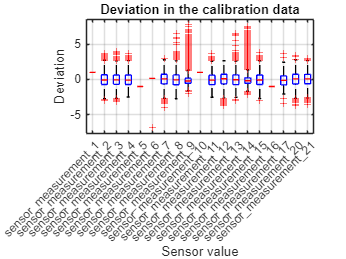

% Boxplot here shows clear deviation in measurement values 9 & 14.
% Potentially the biggest contributors to error detection
% Boxplot calibration data
% Sensor measurements 1, 5, 6, 10 and 16 conribute nothing in terms of
% deviation, so they should be dropped
figure;
boxplot(X_calibration_z, 'Labels',column_labels);
xlabel('Sensor value');
ylabel('Deviation');
xtickangle(45);
grid on;
title('Deviation in the calibration data');

% Drop columns with low deviation 1 5 6 10 16
X_calibration_z(:,[1,5, 6, 10, 16]) = [];

% Drop from column labels 
column_labels(:,[1,5, 6, 10, 16]) = [];

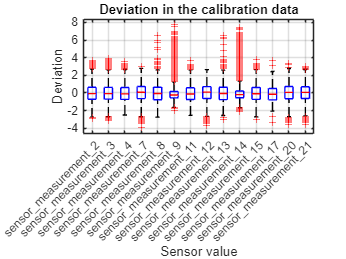

figure;
boxplot(X_calibration_z, 'Labels',column_labels);
xlabel('Sensor value');
ylabel('Deviation');
xtickangle(45);
grid on;
title('Deviation in the calibration data');

% Test data scaling
X_test_z = (X_test - calibration_mean) ./ calibration_std;
Y_test_z = (Y_test - Y_calibration_mean) ./ Y_calibration_std

Y_test_z =     1.5299
    1.5149
    1.4999
    1.4849
    1.4699
    1.4549
    1.4399
    1.4249
    1.4099
    1.3949


% Drop the same columns from test data
X_test_z(:,[1,5, 6, 10, 16]) = [];

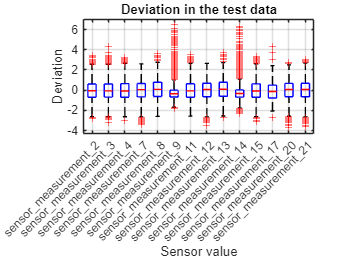

% Boxplot here shows clear deviation in measurement values 9 & 14.
% Potentially the biggest contributors to error detection
% Boxplot test data
figure;
boxplot(X_test_z, 'Labels',column_labels);
xlabel('Sensor value');
ylabel('Deviation')
xtickangle(45);
grid on;
title('Deviation in the test data');

## PLS model Calibration

% Start calibration work from here using the _z values representing the
% standardized and cleaned data

% Quick run on a PLS model with the data
[XL,YL,XS,YS,PLS_BETA,PCTVAR,MSE,stats]= plsregress(X_calibration_z, Y_calibration_z, 10,'cv',5);

intercept = ones(size(X_calibration_z,1),1);

Yfit = [intercept X_calibration_z]*PLS_BETA;
predictions = [ones(size(X_calibration_z ,1),1) X_calibration_z] * PLS_BETA;

% Q2 look
Y_pred_in_r = Yfit;

Q2_in_r = 1 - sum((Y_calibration_z - Y_pred_in_r).^2) / sum((Y_calibration_z - mean(Y_calibration_z)).^2);
disp(['Q-squared for the initial calibration PLS: ', num2str(Q2_in_r)]);

Q-squared for the initial calibration PLS: 0.58911


if Q2_in_r > 0.5
    disp('Good prediction')
else
    disp('Not good prediction')
end

Good prediction


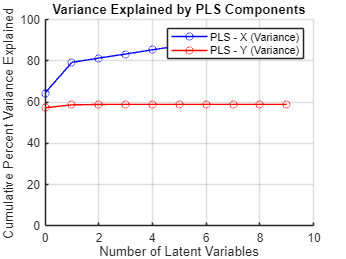

% Plot cumulative variance explained by the PLS components for X and Y
% Most of the variance in X is explained by 4-5 components
figure;
hold on;
plot(0:9, cumsum(100 * PCTVAR(1,:)), '-bo', 'DisplayName', 'PLS - X (Variance)');
plot(0:9, cumsum(100 * PCTVAR(2,:)), '-ro', 'DisplayName', 'PLS - Y (Variance)');
xlabel('Number of Latent Variables');
ylabel('Cumulative Percent Variance Explained');
ylim([0 100]);
legend show;
grid on;
title('Variance Explained by PLS Components');
hold off;

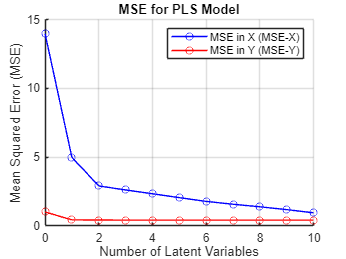

% Plot MSE for different numbers of LVs
figure;
hold on;
plot(0:10, MSE(1,:), 'b-o', 'DisplayName', 'MSE in X (MSE-X)');
plot(0:10, MSE(2,:), 'r-o', 'DisplayName', 'MSE in Y (MSE-Y)');
xlabel('Number of Latent Variables');
ylabel('Mean Squared Error (MSE)');
title('MSE for PLS Model');
legend show;
grid on;
hold off;

% Most impactful components etc.. Remove the data that deviates the least and calibrate the model 
% Fit the model - look at Q2 and R2 values. 
% Good Q2 values should be in the range of 0.5 and above 
% Good R2 values should also be positive and close to one 
% Confusion matrixes to show RUL prediction accuracy...........

% Determine the optimal number of LVs based on previous PLS plots
optimal_LVs = 5;  

% Fit the final model with the optimal number of LVs
[XL_opt, YL_opt, XS_opt, YS_opt, BETA_opt, PCTVAR_opt, MSE_opt, stats_opt] = plsregress(X_calibration_z, Y_calibration_z, optimal_LVs);

% Use the final model to make predictions on the calibration data
Y_calibration_pred_final = [ones(size(X_calibration_z, 1), 1) X_calibration_z] * BETA_opt;

% Calculate R² for the final model (how well it fits the calibration data)
R2_calibration_final = corr(Y_calibration_pred_final, Y_calibration_z)^2;

% Perform k-fold cross-validation manually to calculate Q² for the final model
cv = cvpartition(size(X_calibration_z, 1), 'KFold', 5);
Ypred_cv_final = zeros(size(Y_calibration_z));  % Placeholder for predictions

for i = 1:cv.NumTestSets
    % Training and validation data for this fold
    Xtrain = X_calibration_z(training(cv, i), :);
    Ytrain = Y_calibration_z(training(cv, i));
    Xtest = X_calibration_z(test(cv, i), :);
    
    % Fit PLS model on training data with the optimal number of LVs
    [~, ~, ~, ~, BETA_opt_cv] = plsregress(Xtrain, Ytrain, optimal_LVs);
    
    % Predict on validation (test) data using the final model
    Ypred_cv_final(test(cv, i)) = [ones(size(Xtest, 1), 1) Xtest] * BETA_opt_cv;
end

% Calculate Q² for the final model
Q2_calibration_final = 1 - sum((Ypred_cv_final - Y_calibration_z).^2) / sum((Y_calibration_z - mean(Y_calibration_z)).^2);

% Display R² and Q² values for the final model
fprintf('R² (Final Calibration fit): %.3f\n', R2_calibration_final);

R² (Final Calibration fit): 0.589


fprintf('Q² (Cross-validated prediction for final model): %.3f\n', Q2_calibration_final);

Q² (Cross-validated prediction for final model): 0.588


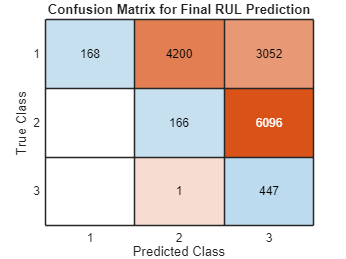


% Confusion matrix to show RUL prediction accuracy
% Assuming RUL prediction is classified into categories (e.g., 'High', 'Medium', 'Low RUL')
RUL_classes_calibration = discretize(Y_calibration_z, 3);  % Discretize into 3 categories
RUL_classes_pred = discretize(Ypred_cv_final, 3);  % Use final predictions

% Confusion matrix
figure;
confusionchart(RUL_classes_calibration, RUL_classes_pred);
title('Confusion Matrix for Final RUL Prediction');

## Test data work

% Create test data prediction model
% Test data Good Q2 values should be in the range of 0.5 and above 
% Test data Good R2 values should also be positive and close to one
% Tariq Jawad


% Test data prediction model
Y_test_pred = [ones(size(X_test_z, 1), 1) X_test_z] * BETA_opt;

% Plot test data predictions vs actual
figure;
plot(Y_test_z, 'ro-', 'DisplayName', 'Actual Test RUL');
hold on;
plot(Y_test_pred, 'bo-', 'DisplayName', 'Predicted Test RUL');
xlabel('Test Data Sample');
ylabel('Normalized RUL');
title('Actual vs Predicted RUL for Test Data');
legend show;
grid on;

% Calculate R² for test data
R2_test_final = corr(Y_test_pred, Y_test_z)^2;
fprintf('R² (Test fit): %.3f\n', R2_test_final);

R² (Test fit): 0.569


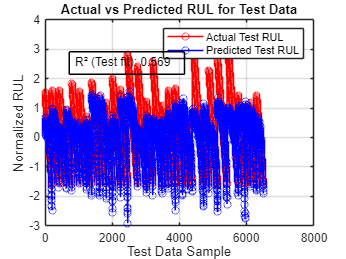


% Display R² value as a text box on the figure
dim = [0.2 0.5 0.3 0.3];
str = ['R² (Test fit): ' num2str(R2_test_final, '%.3f')];
annotation('textbox',dim,'String',str,'FitBoxToText','on');


% Perform k-fold cross-validation for Q² on test data
cv_test = cvpartition(size(X_test_z, 1), 'KFold', 5);
Ypred_cv_test_final = zeros(size(Y_test_z));

for i = 1:cv_test.NumTestSets
    Xtrain = X_calibration_z(training(cv_test, i), :);
    Ytrain = Y_calibration_z(training(cv_test, i));
    Xtest = X_test_z(test(cv_test, i), :);
    [~, ~, ~, ~, BETA_opt_cv_test] = plsregress(Xtrain, Ytrain, optimal_LVs);
    Ypred_cv_test_final(test(cv_test, i)) = [ones(size(Xtest, 1), 1) Xtest] * BETA_opt_cv_test;
end

% Calculate Q² for test data
Q2_test_final = 1 - sum((Ypred_cv_test_final - Y_test_z).^2) / sum((Y_test_z - mean(Y_test_z)).^2);
fprintf('Q² (Test fit): %.3f\n', Q2_test_final);

Q² (Test fit): 0.538


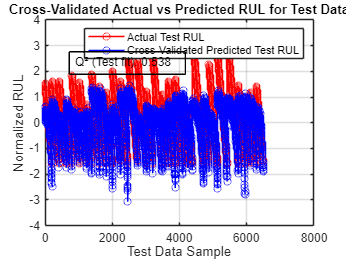


% Plot test Q² cross-validation results
figure;
plot(Y_test_z, 'ro-', 'DisplayName', 'Actual Test RUL');
hold on;
plot(Ypred_cv_test_final, 'bo-', 'DisplayName', 'Cross-Validated Predicted Test RUL');
xlabel('Test Data Sample');
ylabel('Normalized RUL');
title('Cross-Validated Actual vs Predicted RUL for Test Data');
legend show;
grid on;

% Display Q² value as a text box on the figure
dim_q2 = [0.2 0.5 0.3 0.3];
str_q2 = ['Q² (Test fit): ' num2str(Q2_test_final, '%.3f')];
annotation('textbox',dim_q2,'String',str_q2,'FitBoxToText','on');

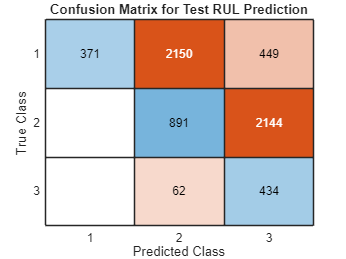


% Confusion matrix to show RUL prediction accuracy for test data
RUL_classes_test = discretize(Y_test_z, 3);  % Discretize into 3 categories
RUL_classes_pred_test = discretize(Y_test_pred, 3);  % Predicted classes
figure;
confusionchart(RUL_classes_test, RUL_classes_pred_test);
title('Confusion Matrix for Test RUL Prediction');